# HW02 - Scuderi - 1937090

# Model Analysis

Case: rigid + 1 elastic mode

Let's assume, for all simulations, the case where some damping is always present (consistent with real life scenarios)

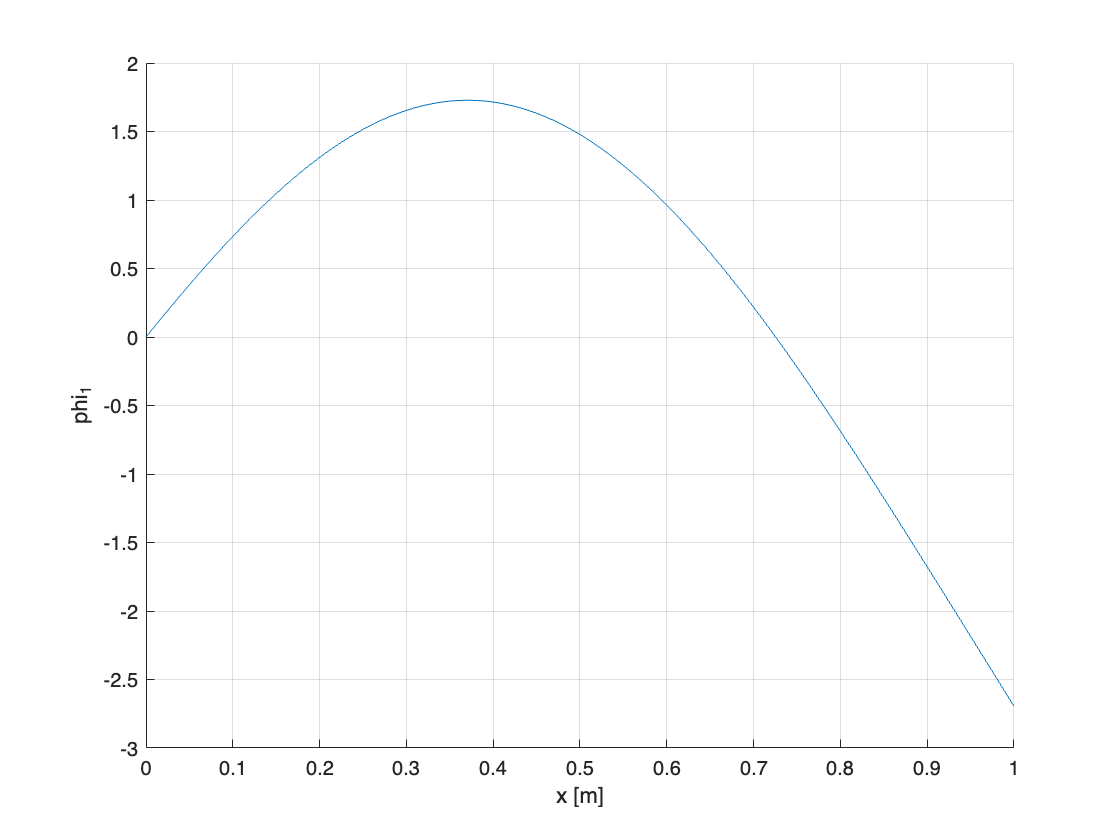

clear all
clc

% Load Parameters in workspace from external file
EulerBeam_Modeling1Mode

s = tf('s');
om = logspace(-2,4,300);

We use the same parameters as for the article ....

% Square of the natural frequencies
disp(' Square of the natural frequencies: ')

 Square of the natural frequencies: 


om1 = sqrt(Om2(1))

om1 = 20.5325

% Vector of Phi'(0)
disp(' Vector of (dPhi/dx)(0): ')

 Vector of (dPhi/dx)(0): 


disp(Phip0)

    7.8259



% Vector of Phi(L)/L
disp(' Vector of Phi(L)/L: ')

 Vector of Phi(L)/L: 


disp(PhiL/L)

   -2.6954



We can build the matrices of the second order model


$$M \ddot q + D \dot q + K q = B_p \tau$$


Considering only 1 elastic modes ($n_e = 1$) the matrices are


$$M = \left[\matrix{J & 0\cr 0 & 1}  \right], \quad
D = \left[\matrix{0 & 0\cr 0 & 2 \zeta_1 \omega_1}  \right]$$



$$K = \left[\matrix{0 & 0\cr 0 & \omega_1^2}  \right], \quad
B_p = \left[\matrix{1 \cr \Phi'_1(0)}  \right]$$


M = [J, 0; 0, 1];
% damping coefficients 
zeta1 = 0.4;
D = [0, 0; 0, 2*zeta1*om1];
K = [0, 0; 0, om1^2];
Bp = [1; Phip0(1)];

State space representation


$$x = \left[\matrix{q \cr \dot q}   \right], \qquad
\dot x = \left[\matrix{ 0 & I \cr -M^{-1}K & -M^{-1}D}   \right] x + \left[\matrix{0 \cr M^{-1}B_p}   \right]u $$


We can consider three different outputs:

- Joint Angle $\vartheta_c$: angle at the beam base 

- Tip angle $\vartheta_t$: angle at the tip approximated by $\vartheta_c + \sum_{i=1}^{n_e}\frac{\Phi_i(L)}{L}$

- Point P angle $\theta_P :$angle at a fixed point P approximated by $\vartheta_c + \sum_{i=1}^{n_e}\frac{\Phi_i(x_P)}{x_P}\ ; \quad x_p \in (0,L)$

We place strategically three points $P_1 ,P_2 ,P_3$ at $x_{P_{i\;} } =\left\lbrack \frac{L}{4},\frac{L}{2},\frac{3L}{4}\right\rbrack$.

% A_no_d = [zeros(2),eye(2);-inv(M)*K, zeros(2)];  % no damping

% System's Dynamical Matrices 
A_d    = [zeros(2),eye(2);-inv(M)*K, -inv(M)*D]; % damping
B      = [zeros(2,1);inv(M)*Bp];

C_bas  = [1, Phip0(1), 0, 0];
C_tip  = [1, PhiL(1), 0, 0];
C_P1 = [1, phi(26)/(L/4), 0, 0];
C_P2 = [1, phi(51)/(L/2), 0, 0];
C_P3 = [1, phi(76)/(3*L/4), 0, 0];

So we can define the following state space systems

% Joint (base) SS representation
FlexBasD   = ss(A_d,B,C_bas,0);
%FlexBasNoD = ss(A_no_d,B,C_bas,0);

% Tip SS representation
FlexTipD   = ss(A_d,B,C_tip,0);
%FlexTipNoD = ss(A_no_d,B,C_tip,0);

% Point P SS representation
FlexP1D   = ss(A_d,B,C_P1,0);
FlexP2D   = ss(A_d,B,C_P2,0);
FlexP3D   = ss(A_d,B,C_P3,0);

and transfer functions

% Joint (Base) TF: Pc
[NumC, DenC] = ss2tf(A_d,B,C_bas,0);
Pc = tf(NumC, DenC);
zpk(Pc)

ans =
 
  67.174 (s^2 + 1.45s + 37.21)
  ----------------------------
   s^2 (s^2 + 16.43s + 421.6)
 
Continuous-time zero/pole/gain model.
Model Properties


% Tip TF: Pt
[NumT, DenT] = ss2tf(A_d,B,C_tip,0);
Pt = tf(NumT, DenT);
zpk(Pt)

ans =
 
  -15.165 (s-16.44) (s+10.02)
  ---------------------------
  s^2 (s^2 + 16.43s + 421.6)
 
Continuous-time zero/pole/gain model.
Model Properties


% Point P_i TF: Pi
[NumP1, DenP1] = ss2tf(A_d,B,C_P1,0);
Pp1 = tf(NumP1, DenP1);
zpk(Pp1)

ans =
 
  53.368 (s^2 + 1.825s + 46.84)
  -----------------------------
   s^2 (s^2 + 16.43s + 421.6)
 
Continuous-time zero/pole/gain model.
Model Properties



[NumP2, DenP2] = ss2tf(A_d,B,C_P2,0);
Pp2 = tf(NumP2, DenP2);
zpk(Pp2)

ans =
 
  29.059 (s^2 + 3.351s + 86.01)
  -----------------------------
   s^2 (s^2 + 16.43s + 421.6)
 
Continuous-time zero/pole/gain model.
Model Properties


[NumP3, DenP3] = ss2tf(A_d,B,C_P3,0);
Pp3 = tf(NumP3, DenP3);
zpk(Pp3)

ans =
 
  3.6387 (s^2 + 26.76s + 686.9)
  -----------------------------
   s^2 (s^2 + 16.43s + 421.6)
 
Continuous-time zero/pole/gain model.
Model Properties


As expected, the Plant with the tip angle as output is non minimum phase and all plants have stable poles.

Let's save the Right Half Plane (real) zero in a variable, so we can use it later

% Tip angle output zeros
disp('Pt zeros')

Pt zeros


zt = zero(Pt);
z_rhp = zt(1)

z_rhp = 16.4447

Since only the Transfer Function associated to the tip angle is non minimum phase. Therefore, we'll use Pt as a case study, and confront the results with the Pc as a reference for performance comparison.

To study the sensitivity integrals, we'll use some simple PID's controller to analize the limitations which arise from NMP systems. 

# Limitations

Let's explore limitations at first with some simple PID controllers

## PID "dummy" controllers

ops = pidtuneOptions('DesignFocus','reference-tracking');

% PID Controllers
[C_PIDc,info1] = pidtune(Pc,'PIDF',ops); 
[C_PIDt,info2] = pidtune(Pt,'PIDF',ops);

[C_PIDp1,infop1] = pidtune(Pp1,'PIDF',ops); 
[C_PIDp2,infop2] = pidtune(Pp2,'PIDF',ops);
[C_PIDp3,infop3] = pidtune(Pp3,'PIDF',ops);

% PID CL Sensitivities
CLoop_PIDc = loopsens(Pc,C_PIDc);  % resulting sensitivities for c.
CLoop_PIDt = loopsens(Pt,C_PIDt);  % resulting sensitivities tip

CLoopP1 = loopsens(Pp1,C_PIDp1); 
CLoopP2 = loopsens(Pp2,C_PIDp2); 
CLoopP3 = loopsens(Pp3,C_PIDp3);


We know that for any minimum phase and stable Plant, no matter the controller or specifications, the Loop function has a **roll-off condition** at the crossover frequency $\omega_c$ that is:

** the slope cannot be steeper than -40 dB/decade**

In fact, by plotting the Loop function magnitudes for every plant but Pt(s) (non min phase), we get:

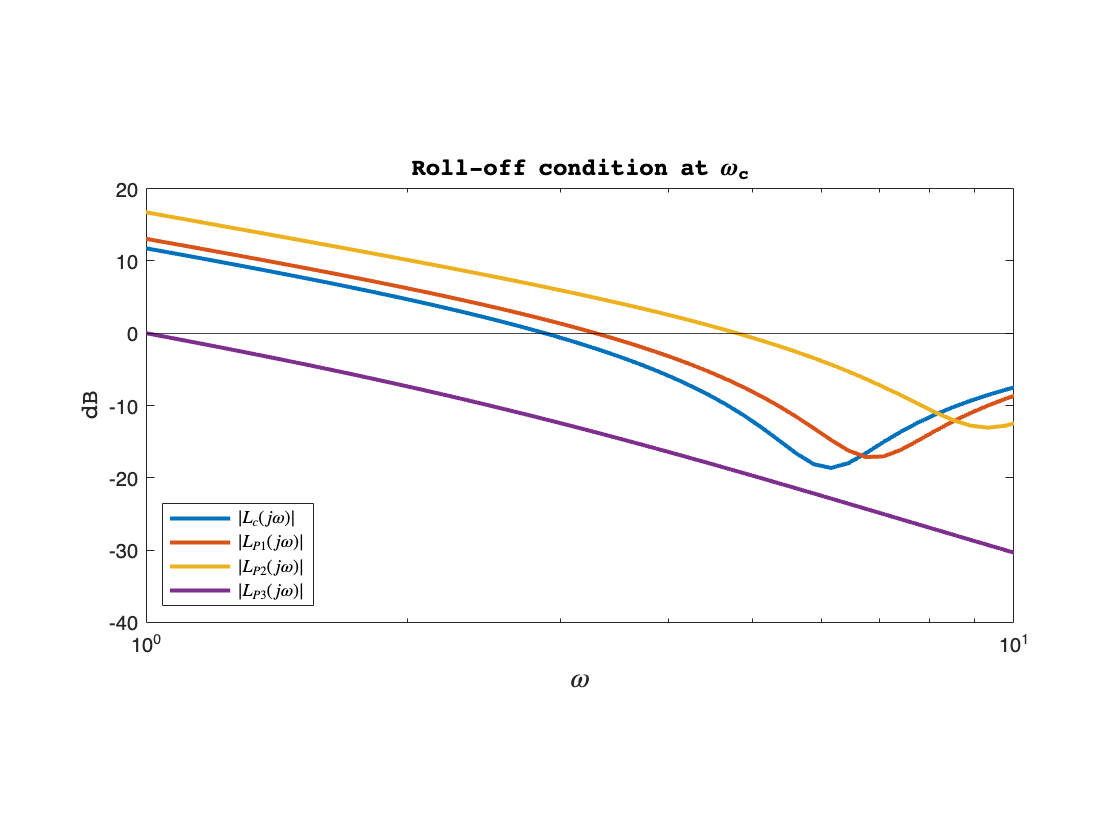

% Loop Function's BODE
[MagOLc,~] = bode(Pc*C_PIDc, om);

[MagOLp1,~]=bode(Pp1*C_PIDp1,om);       
[MagOLp2,~]=bode(Pp2*C_PIDp2,om);    
[MagOLp3,~]=bode(Pp3*C_PIDp3,om);

figure()
grid on
semilogx(om,20*log10(MagOLc(1,:)),om,20*log10(MagOLp1(1,:)),...
    om,20*log10(MagOLp2(1,:)), om,20*log10(MagOLp3(1,:)), 'Linewidth', 2);
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
yline(0,'-k');
legend('$|L_{c}(j\omega)|$','$|L_{P1}(j\omega)|$','$|L_{P2}(j\omega)|$',...
    '$|L_{P3}(j\omega)|$','Interpreter','latex','Location','southwest');
title(['Roll-off condition at \omega_c'],'FontName','courier','FontSize',12);
xlim([1,10])
pbaspect([2 1 1])

## Sensitivity Integrals

We have two Systems with Loop function that has relative degree two. One of them is Non-Minimum-Phase. Threfore we can calculate the Bode Sensitivity Integral for the MP system, and the Poisson Integral for the other  one, and verify they both converge to zero (since there's no RHP poles).

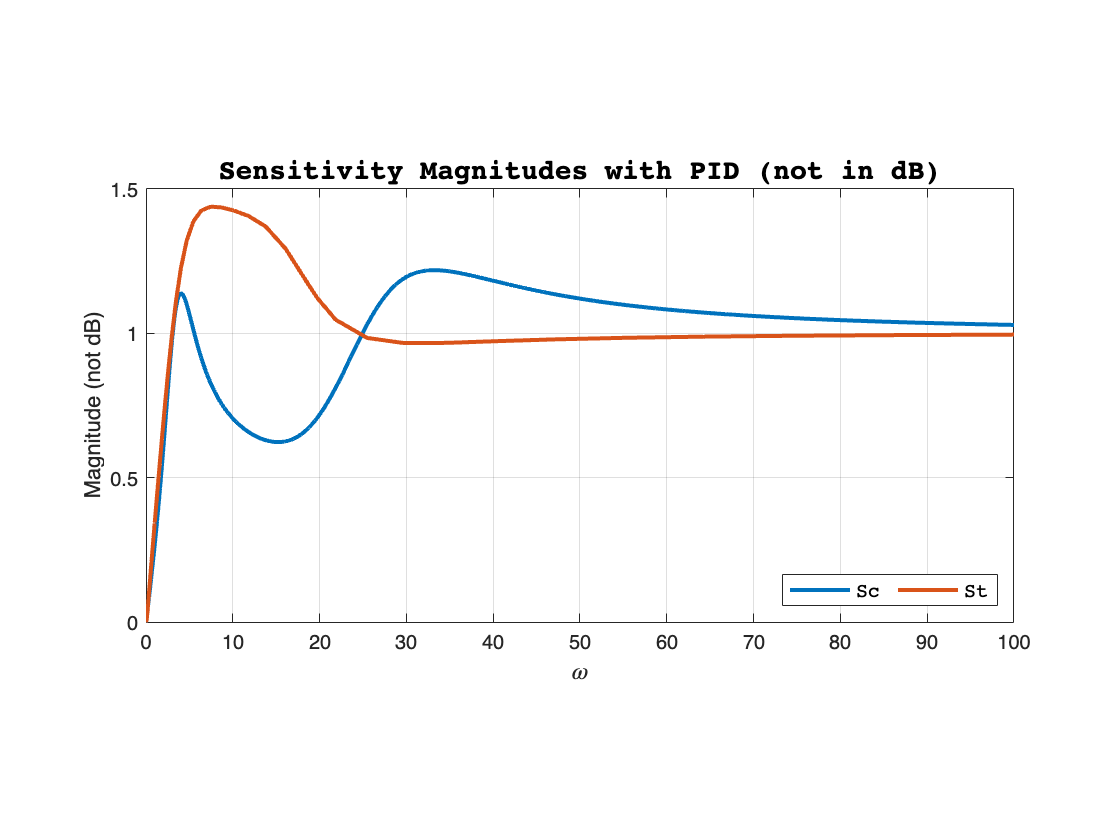

% I use a large horizon of frequency for aproximating integration up to +inf
% Use larger sampling freq. up to 100
wc = [0.001:0.001:100, 100:0.1:10^5];
[magSc,~,~]= bode(CLoop_PIDc.So, wc); % Sensitivity magnitude for each Sampled Frequency

% For the NMP system I use sampled frequencies since it's computationally
% much faster and the "regular" shape of the sensitivity allows such a
% semplification
[~, ~, wt] = bode(CLoop_PIDt.So); % Sampled Frequencies
magSt = bode(CLoop_PIDt.So, wt); % Sensitivity magnitude for each Sampled Frequency

% Integrals Plots
figure()
plot(wc, magSc(:), wt, magSt(:),LineWidth=2)
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('Magnitude (not dB)')
title('Sensitivity Magnitudes with PID (not in dB)', 'FontName','courier','FontSize',14)
legend('Sc','St' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
xlim([0,100])
grid
 pbaspect([2 1 1])

bode_integral_Sc = trapz(wc, log(magSc)); % Integral computation
disp(['Bode Integral for Min Phase Plant: ', num2str(bode_integral_Sc)])

Bode Integral for Min Phase Plant: 0.015807


% Use sum since I used a vector representation for weight
bode_integral_St = sum(trapz(wt, log(magSt(:)).*(2*(z_rhp)/((z_rhp)^2+wt.^2))));
disp(['Poisson Integral for NMP Plant: ', num2str(bode_integral_St)])

Poisson Integral for NMP Plant: 0.0016729


As expected, the Bode Sensitivity Integral for the MP system converges to zero (with some error due to numerical approximation). On the other hand, the Weighted Bode Sensitivity Integral also converges to zero (due to RHP zero), with a small error.

Just to validate the integration method, let's calculate the bode sensitivities integrals for the other Plants, to verify they converge to zero.

disp(['Bode Integral for Pp1: ', num2str(trapz(wc, log(bode(CLoopP1.So, wc))))])

Bode Integral for Pp1: 0.016276


disp(['Bode Integral for Pp2: ', num2str(trapz(wc, log(bode(CLoopP2.So, wc))))])

Bode Integral for Pp2: 0.017439


disp(['Bode Integral for Pp3: ', num2str(trapz(wc, log(bode(CLoopP3.So, wc))))])

Bode Integral for Pp3: 0.016293


### Tail frequency computation

% Find Tail Frequency
[H,w] = freqresp(Pc*C_PIDc,100:1:200);
H = squeeze(H);
w = squeeze(w);

eps = 0.01;

w_tail = -1;
for i=1:length(H)
    if (abs(H(i)) < eps)
        w_tail = w(i)
        break
    end
end

w_tail = 168

bound = w_tail*log(1/(1-eps));
% w_tail = 170;
Om_tail = w_tail:0.01:10000;
[magSc_tail, ~, Om] = bode(CLoop_PIDc.So, Om_tail);

% Very much approximated
tail_int = trapz(Om, log(magSc_tail))

tail_int = 1.6239

### $H_\infty$ control "without" Limitations (MP)

%% Sensitivity Weight
Msc = 1.01;
B3sc = 2;
Asc = 0.01;
nc = 1;
wSc = ((s/(Msc)^(1/nc)+B3sc)/(s+B3sc*(Asc)^(1/nc)))^nc;

wSuc = 1/10;


% H_inf controller
[Cc,CLc,GAMc] = mixsyn(Pc,wSc, wSuc,[]);
GAMc

GAMc = 1.0306

t =  [0:0.01:10];

% H_inf sensitivities "compromise"
CLoop_c = loopsens(Pc,Cc);
[y_PIDc,~] = step(CLoop_PIDc.To, t);    % PID base Response
[yc,~] = step(CLoop_c.To, t);    % H_inf base Response


#### Step Response comparison

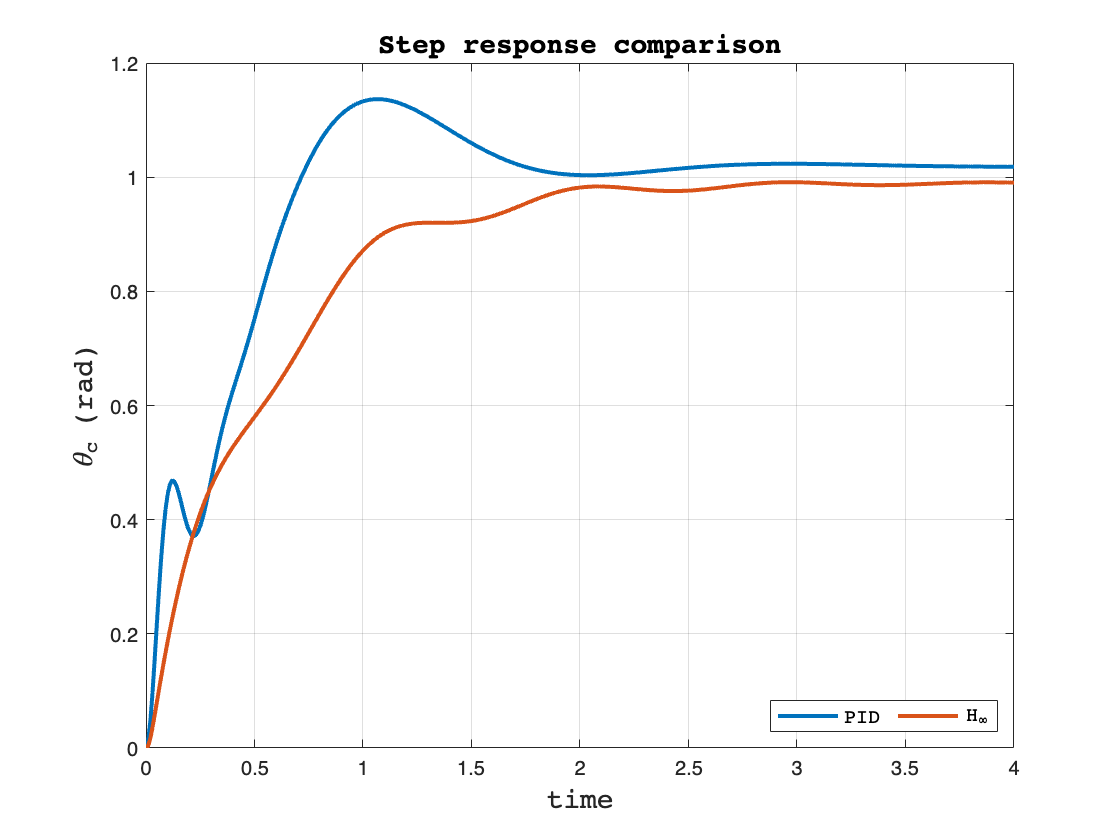

figure()
plot(t,y_PIDc,t,yc,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('\theta_c (rad)','FontName','courier','FontSize',14)
title('Step response comparison', 'FontName','courier','FontSize',14)
legend('PID', 'H_\infty','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
xlim([0,4])

#### Step control effort comparison

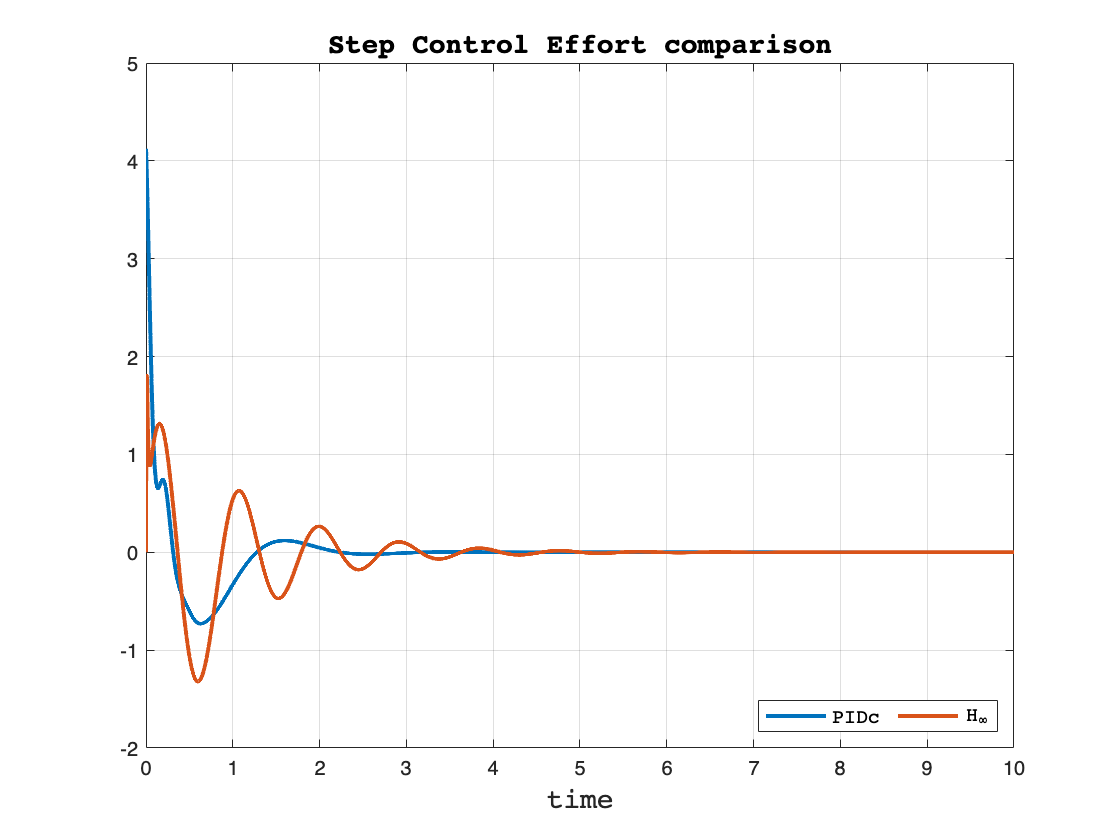

t = 0:0.001:10;
[u_PIDc,~] = step(CLoop_PIDc.CSo, t);    % PID base Control Effort
[u_c,~] = step(CLoop_c.CSo, t);    % H_inf base Control Effort

figure
plot(t,u_PIDc, t,u_c,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
title('Step Control Effort comparison', 'FontName','courier','FontSize',14)
legend('PIDc' , 'H_\infty','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

### $H_\infty$ control with Limitations (NMP)

We can try to outperform the "dummy" PID controller via $H_\infty
$ control. However, we must be aware of the limitations  that arise when dealing with a non minimum phase Plant. Let's be smart at assigning the weights of the sensitivities and find a good compromise to keep the waterbed effect under control.

#### Sensitivity peak bound

For the NMP system, with $z\approx 16\ldotp 4447\;$  we have:


$$ \|{S(s)  w_S(s)\} \|_{\infty} < 1 
\\with:
\\\|{S(s)  w_S(s)\} \|_{\infty} \geq |w_S(z)|
$$


and therefore we need to impose:

$|w_S(z)| < 1$.

To avoid oscillatory beahaviors and peaks, we need to copromise in terms of bandwidth. Setting Ms = 2 and As = 0.01, we have an upperbound for the sensitivity bandwidth: $B_{3S} <\frac{z}{2}\approx 8$. However, such high bandwidth would come at the price of high control effort and sensitivity peak, due to the waterbed effect. Sacrificing bandwidth, we can still achieve faster convenrgence, but significantly reducing tracking error for constant references and oscillatory behaviors.

%% Sensitivity Weight 1: Compromise
Ms1 = 1.1;
B3s1 = 1.4;
As1 = 0.001;
n1 = 1;

%% Sensitivity Weight 2: Greedy
Ms2 = 3;
B3s2 = 7;
As2 = 0.01;

wS1 = ((s/(Ms1)^(1/n1)+B3s1)/(s+B3s1*(As1)^(1/n1)))^n1;
wS2 = ((s/(Ms2)^(1/n1)+B3s2)/(s+B3s2*(As2)^(1/n1)))^n1;

wSu1 = 1/10;
wSu2 = 1/50;

% H_inf sensitivities "compromise"
[C1t,CL1t,GAM1t] = mixsyn(Pt,wS1, wSu1,[]);
GAM1t 

GAM1t = 1.0526

% H_inf controller "greedy"
[C2t,CL2t,GAM2t] = mixsyn(Pt,wS2, wSu2,[]);
GAM2t

GAM2t = 1.0832

% H_inf sensitivities
CLoop_t1 = loopsens(Pt,C1t);            
CLoop_t2 = loopsens(Pt,C2t);

% Extract Bode Magnitudes

[magSt1,~]=bode(CLoop_t1.Si,om);         % sensitivity
[magCSt1,~]=bode(CLoop_t1.CSo,om);         % control sensitivity
[magTt1,phaseTt1]=bode(CLoop_t1.Ti,om);         % complementary sensitivity

[magSt2,~]=bode(CLoop_t2.Si,om);         % sensitivity
[magCSt2,~]=bode(CLoop_t2.CSo,om);         % control sensitivity
[magTt2,phaseTt2]=bode(CLoop_t2.Ti,om);         % complementary sensitivity

% Weights
[magWS1,~]=bode(1/wS1,om);
[magWSu1,~]=bode(1/wSu1,om);

[magWS2,~]=bode(1/wS2,om);
[magWSu2,~]=bode(1/wSu2,om);
[magWSu2,~]=bode(1/wSu2,om);

## Plotting Sensitivitis Magnitudes

#### Sensitivity

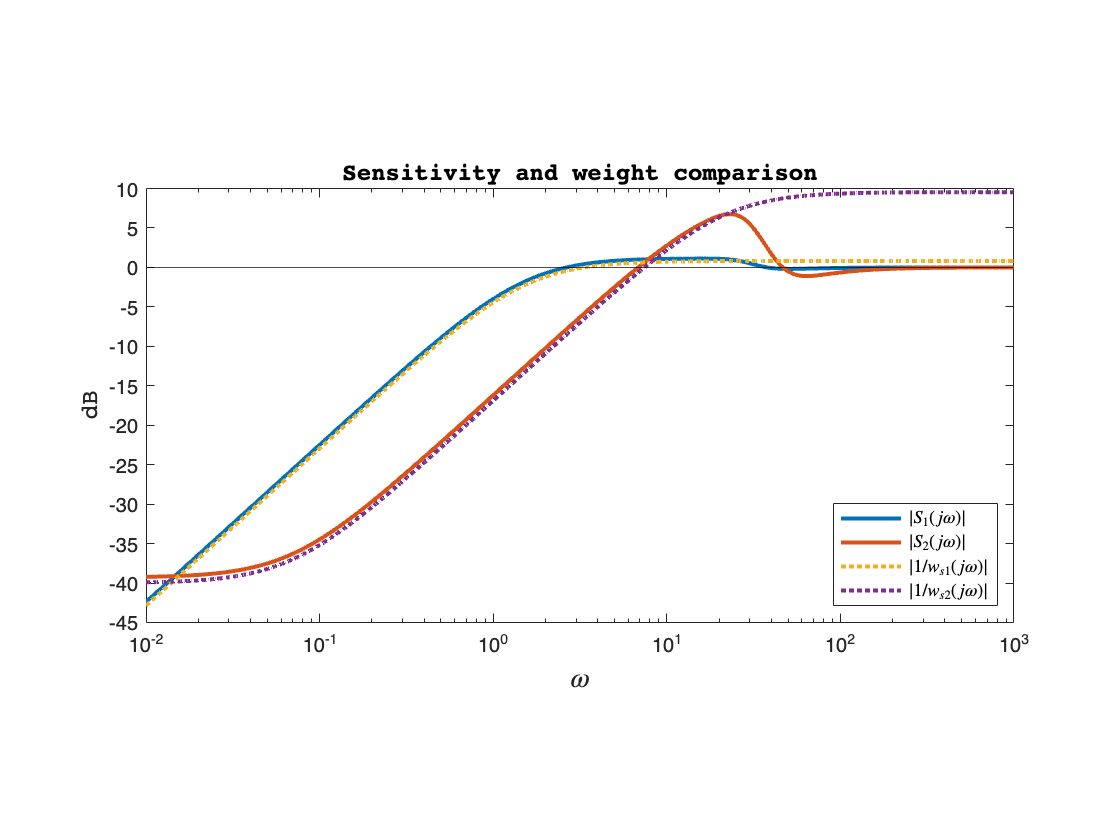

figure()
semilogx(om,20*log10(squeeze(magSt1)),om,20*log10(squeeze(magSt2)),...
    om,20*log10(squeeze(magWS1)),':', om,20*log10(squeeze(magWS2)),':', 'Linewidth', 2);
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
yline(0,'-k');
legend('$|S_{1}(j\omega)|$','$|S_{2}(j\omega)|$','$|1/w_{s1}(j\omega)|$',...
    '$|1/w_{s2}(j\omega)|$','Interpreter','latex','Location','southeast');
title(['Sensitivity and weight comparison'],'FontName','courier','FontSize',12);
xlim([10^-2, 10^3])
ylim([-45,10])
pbaspect([2 1 1])

This Plotting perfectly represents the waterbed effect. Pushing bandwidth with the second controller means increasing the "negative area" of the sensitivity, which in fact forms a large "positie" peak.

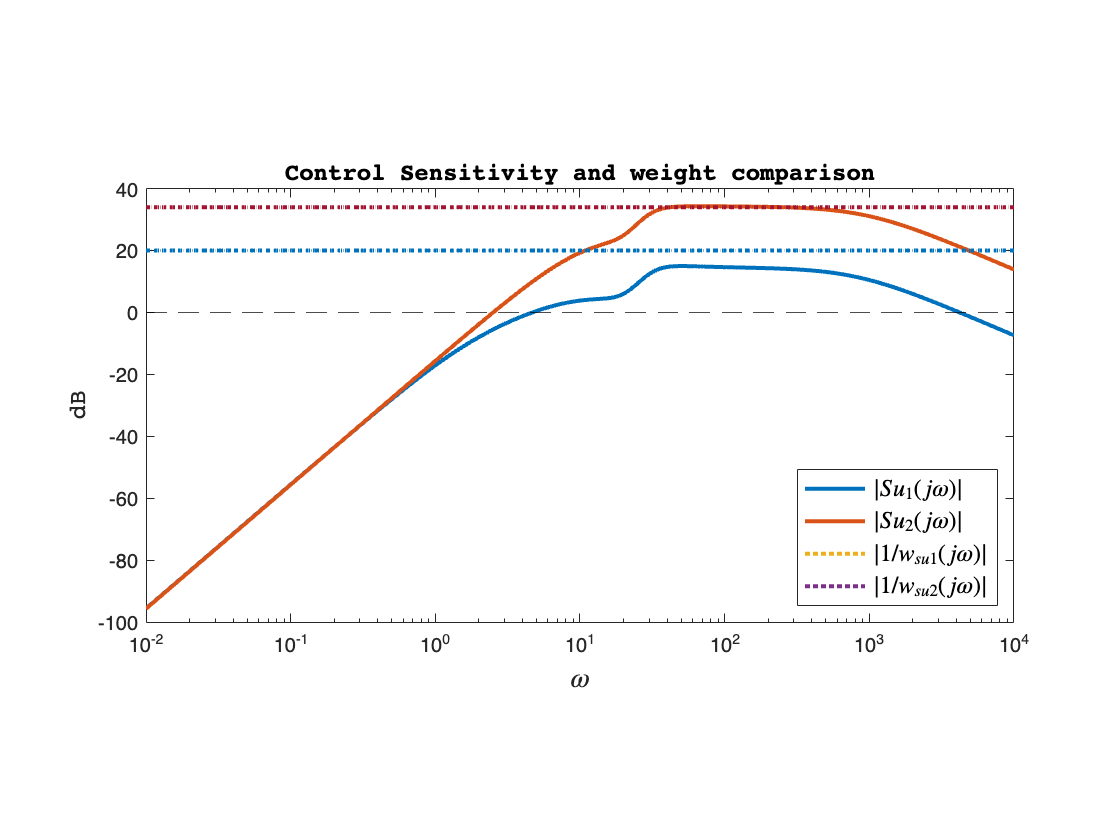

figure()
semilogx(om,20*log10(squeeze(magCSt1)),om,20*log10(squeeze(magCSt2)),...
    om, 20*log10(1/wSu1)*ones(length(magCSt1)),':', om, 20*log10(1/wSu2)*ones(length(magCSt2)),':','Linewidth', 2)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
yline(0,'--k');
legC = legend('$|Su_{1}(j\omega)|$','$|Su_{2}(j\omega)|$','$|1/w_{su1}(j\omega)|$',...
    '$|1/w_{su2}(j\omega)|$','Interpreter','latex','Location','southeast');
set(legC,'FontSize',12)
title(['Control Sensitivity and weight comparison'],'FontName','courier','FontSize',12);
pbaspect([2 1 1])

This plotting is a direct consequence of the design choices made for the two controllers. Pushing bandwidth requires higher control efforts, threfore higher peaks in the control sensitivity function at high frequency.

#### Complementary Sensitivities

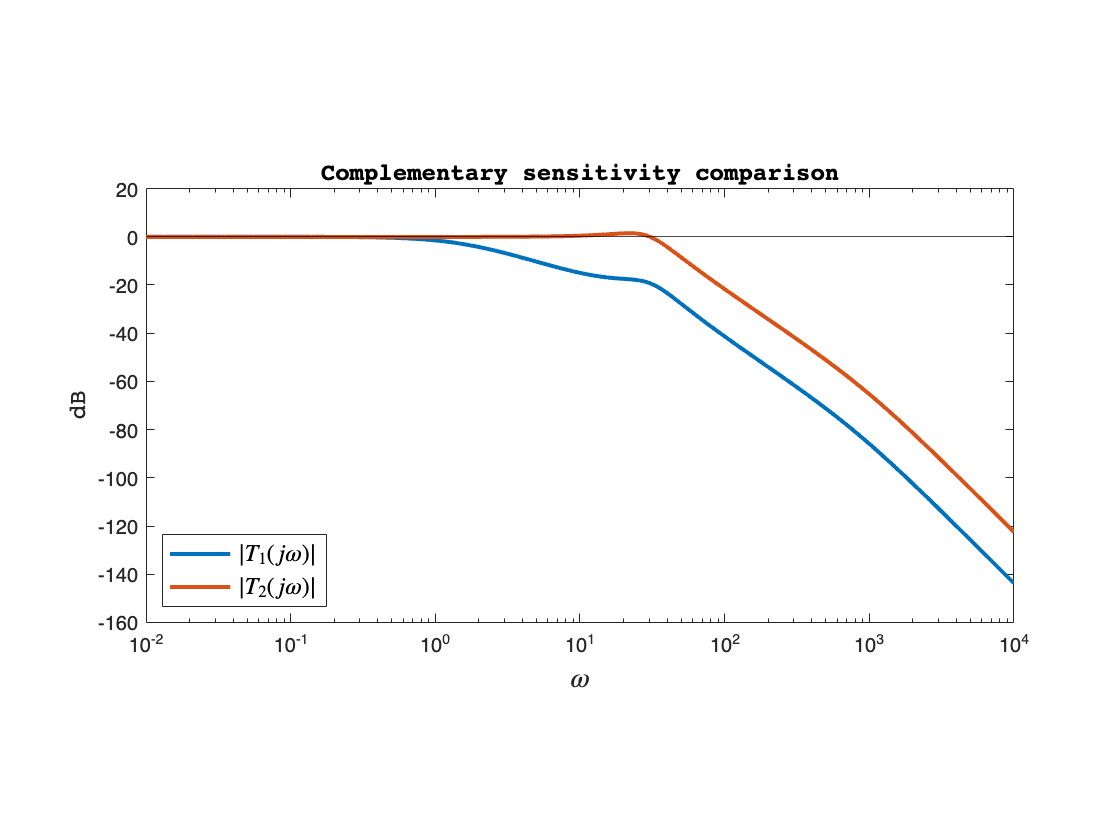

figure()
semilogx(om,20*log10(magTt1(1,:)),om,20*log10(magTt2(1,:)),...
     'Linewidth', 2)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
yline(0,'-k');
legC = legend('$|T_{1}(j\omega)|$','$|T_{2}(j\omega)|$','Interpreter','latex','Location','southwest');
set(legC,'FontSize',12)
title(['Complementary sensitivity comparison'],'FontName','courier','FontSize',12);
pbaspect([2 1 1])

The first controller is clearly more performing in terms of noise rejection, thanks to its lower bandwidth. As for tracking sinusoidal references, the second one will be able to track higher frequency signals with no attenuation (but possibly, still with a certain phase),

### Step response Comparisons

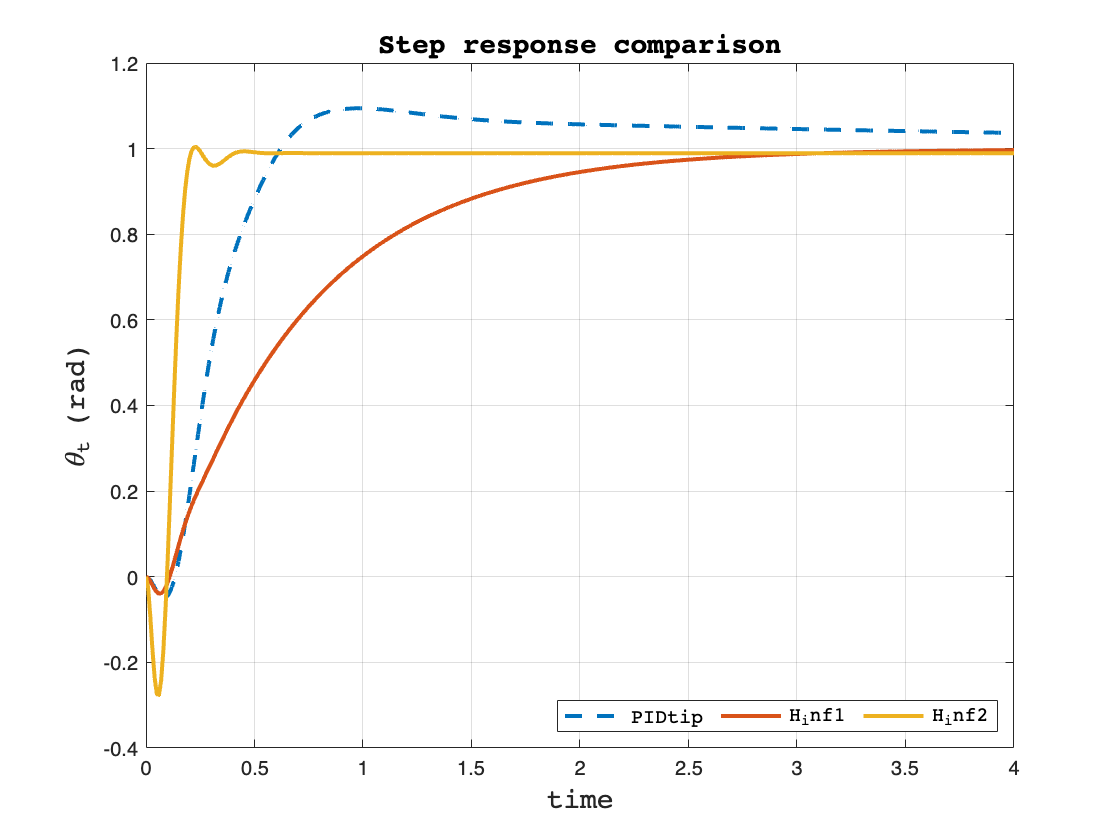

t = 0:0.01:10;
%% Step response
[y1_PIDt,~] = step(CLoop_PIDt.To, t);    % PID Tip Response
[y1_t,~] = step(CLoop_t1.To, t);        % H-inf "compromising" Tip Response
[y2_t,~] = step(CLoop_t2.To, t);        % H-inf "greedy" Tip Response

figure
plot(t,y1_PIDt,'--',t,y1_t,t,y2_t,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('\theta_t (rad)','FontName','courier','FontSize',14)
title('Step response comparison', 'FontName','courier','FontSize',14)
legend('PIDtip' , 'H_inf1', 'H_inf2','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
xlim([0,4])

The "greedy approach" clearly pays in terms of rise time, but also presents osbcillations in the trasnsient. Such obscillations are much less present in the "compromising" H-infinity controller, which still presents an acceptable convergence time and very small tracking error already at 2 seconds.

### Step control effort comparison

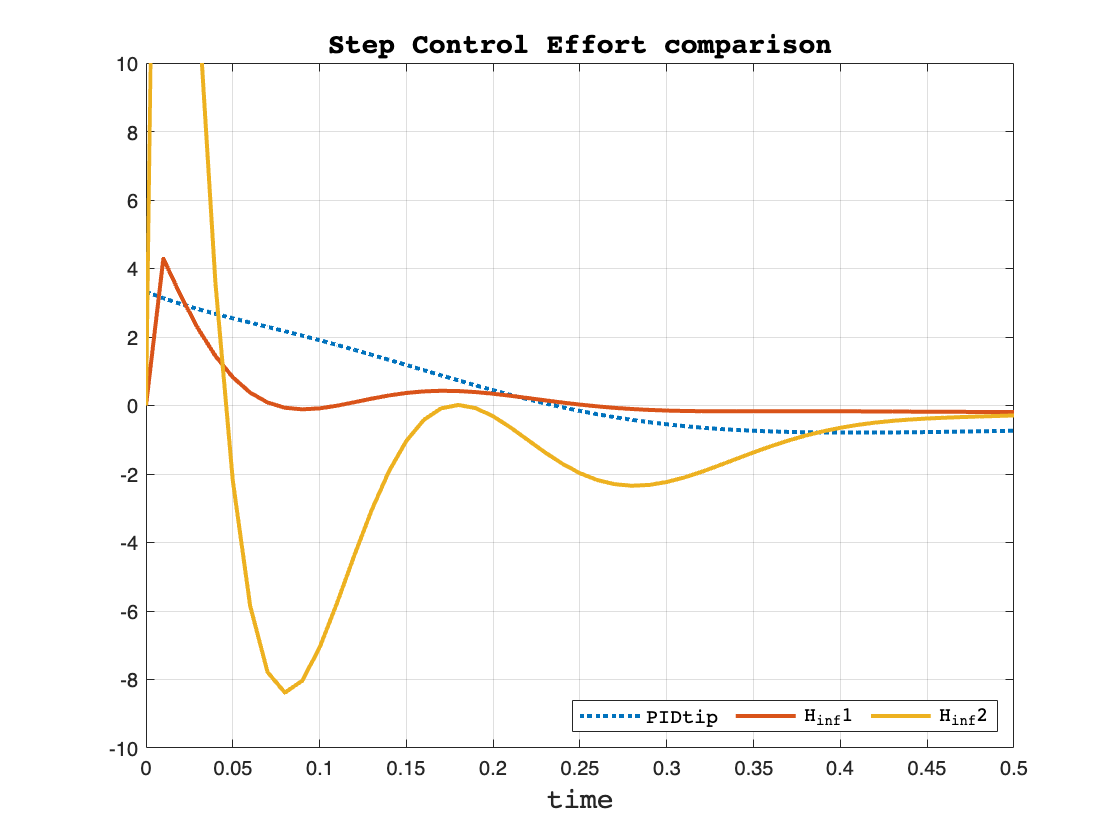

%% Step Control Effort

[u1_PIDt,~] = step(CLoop_PIDt.CSo, t);    % PID Tip Control Effort
[u1_t,~] = step(CLoop_t1.CSo, t);        % H-inf "compromising" Tip Control Effort
[u2_t,~] = step(CLoop_t2.CSo, t);        % H-inf "greedy" Tip Control Effort

figure
plot(t,u1_PIDt,':',t,u1_t,t,u2_t,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
title('Step Control Effort comparison', 'FontName','courier','FontSize',14)
legend('PIDtip', 'H_{inf}1', 'H_{inf}2','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
xlim([0,0.5])
ylim([-10,10])

The required control effort for the second H-infinity coltroller is 10 times larger than the other ones

# Robust Stability

Let's assume two sources of uncertainty:

- **Unceirtanty of the Parameters:** To make the simulation more realistic, let's assume that the damping coefficient  $\zeta_1$ has a small multiplicative uncertainty, while the load at the tip can very much vary (and therefore the Inertia $J_{tip} $, which directly affects the Inertia $\left.J,\right)$. Let's model the load mass as solid sphere, with $J_{tip,UNC} = \frac{2}{5}J_{tip,UNC}R^2\ ,\ with\ R = 0.1$

- **Unmodelled Dynamics: **due to the extreme semplification of the model (infinite dimensional and non linear approximated to one dimensional and linear) we can add this type of source of uncertainty as well


$$\zeta_{1,UNC} =  [(1-10\%)\zeta_{1}, (1+10\%)\zeta_{1}] = [0.32,0.48]
\\m_{tip,UNC} = m_{tip}+m_{extra}\ , with\ m_{extra}\in[0,0.5]
$$


which implies, since m_{tip}=0 in our nominal plant:


$$J_{unc} = J+m_{tip,UNC}L^2 + J_{tip,UNC} = J+m_{tip,UNC}(L^2+\frac{2}{5}R^2)\ \rightarrow\ J_{unc} \in[0.1687,0.6707]$$


### Uncertain Plant (only parametric uncertainty)

% This file, once executed, gives in output an array of evenly spaced
% values of the parameters, for each value of Mt in [0, 0.5]

EulerBeam_Modeling1Mode_Uncertain

#### Uncertain (real) Parameters 

% Mass at tip-dependant parameters
om1_unc = ureal('om1',sqrt(Om2(2)),'Range',[sqrt(Om2(51)) sqrt(Om2(1))]);
om1_unc2 = ureal('om2',Om2(2),'Range',[Om2(51) Om2(1)]);
Phip0_unc = ureal('Phi0',Phip0(2),'Range',[Phip0(51) Phip0(1)]);
J_unc = ureal('J',J(2),'Range',[J(1) J(51)]);
PhiL_unc = ureal('PhiL',PhiL(2),'Range',[PhiL(1) PhiL(51)]);

% Uncertainty on damping coefficient (10%)
zeta1_unc = ureal('zeta1',zeta1,'Percentage',10);

#### Uncertain Matrices for state space

%Uncertain paraeters matrices
M_unc = [J_unc, 0; 0, 1];
D_unc = [0, 0; 0, 2*zeta1_unc*om1_unc];
K_unc = [0, 0; 0, om1_unc2];
Bp_unc = [1; Phip0_unc];

% Uncertain Dynamics' Matrices
A_d_unc    = [zeros(2),eye(2);-inv(M_unc)*K_unc, -inv(M_unc)*D_unc]; % damping
B_unc      = [zeros(2,1);inv(M_unc)*Bp_unc];

C_bas_unc  = [1, Phip0_unc, 0, 0];
C_tip_unc  = [1, PhiL_unc, 0, 0];

%{
% Unused Later
C_P1_unc = [1, phi(26)/(L/4), 0, 0];
C_P2_unc = [1, phi(51)/(L/2), 0, 0];
C_P3_unc = [1, phi(76)/(3*L/4), 0, 0];
%}


#### Uncertain (real) Transfer Functions

% Base ss representation
Pc_unc = ss(A_d_unc,B_unc,C_bas_unc,0);

% Tip ss representation
Pt_unc   = ss(A_d_unc,B_unc,C_tip_unc,0);

## CASE I: Structured (REAL) Parametric Uncertainty

Using the structured uncertainty (assuming all parameters real and varying in the ranges defined above), let's test if the controllers designed before are actually robustly stabilizing the plant.

% Base uncertain Loop Function
Lc_unc  = Cc*Pc_unc;
CLc_unc = feedback(Lc_unc,1);
[stabmargc,wcuc] = robstab(CLc_unc)

stabmargc = struct with fields:
           LowerBound: 1.0397
           UpperBound: 1.0417
    CriticalFrequency: 6.3177e-06


wcuc = struct with fields:
        J: 3.0784e+05
     Phi0: 6.8851
      om1: 12.5151
      om2: 206.6945
    zeta1: 0.3583


The 

% Tip "non-greedy" uncertain Loop Function
L1_unc  = C1t*Pt_unc;
CL1_unc = feedback(L1_unc,1);
[stabmarg1,wcu1] = robstab(CL1_unc)

stabmarg1 = struct with fields:
           LowerBound: 1.0397
           UpperBound: 1.0417
    CriticalFrequency: 0


wcu1 = struct with fields:
        J: 2.3238e+03
     Phi0: 6.9605
     PhiL: -1.5310
      om1: 12.5155
      om2: 154.7332
    zeta1: 0.4417


% Tip "greedy" uncertain Loop Function
L2_unc  = C2t*Pt_unc;
CL2_unc = feedback(L2_unc,1);

[stabmarg2,wcu2] = robstab(CL2_unc)

stabmarg2 = struct with fields:
           LowerBound: 0.9355
           UpperBound: 0.9398
    CriticalFrequency: 13.4940


wcu2 = struct with fields:
        J: 0.2313
     Phi0: 7.8177
     PhiL: -2.6881
      om1: 15.2361
      om2: 232.9874
    zeta1: 0.3624


The greedy approach leads to non robust stability

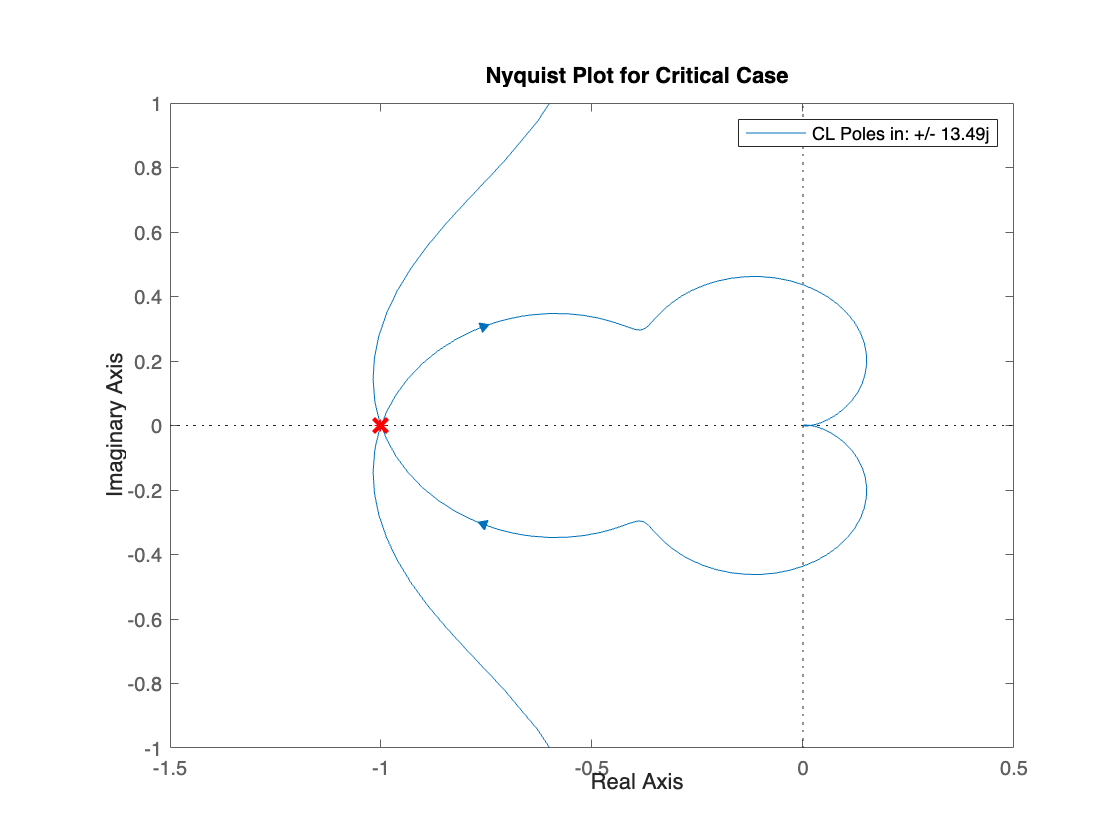

L2_limit = usubs(L2_unc,wcu2);
figure()
nyquist(L2_limit), axis([-1.5,0.5,-1,1]), hold on
plot(-1, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2);
title("Nyquist Plot for Critical Case")
legend("CL Poles in: +/- 13.49j")

lim_poles = pole(1/(1+L2_limit))

lim_poles = 1.0e+02 *

  -9.6201 + 0.0000i
  -0.1669 + 0.2922i
  -0.1669 - 0.2922i
  -0.2452 + 0.0000i
  -0.0439 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.1349i
   0.0000 - 0.1349i


## CASE II: Unstructured (Full Complex) Parametric Uncertainty

% Sampled uncertain plants
Pc_unc_samp = gridureal(Pc_unc,20);
Pt_unc_samp = gridureal(Pt_unc,20);

Pc_nom = Pc_unc.nominal;
Pt_nom = Pt_unc.nominal;

% Disc approximation
Delta  = ultidyn('delta',[1 1]); 


### Additive Unstructured Uncertainty

% ucover additive
[P_add_c,info_add_c] = ucover(Pc_unc_samp,Pc_nom,3,'Additive');
[P_add_t,info_add_t] = ucover(Pt_unc_samp,Pt_nom,3,'Additive');

%uncertanty weights
Wc_add = info_add_c.W1;
Wt_add = info_add_t.W1;


#### Choice of the additive weights 

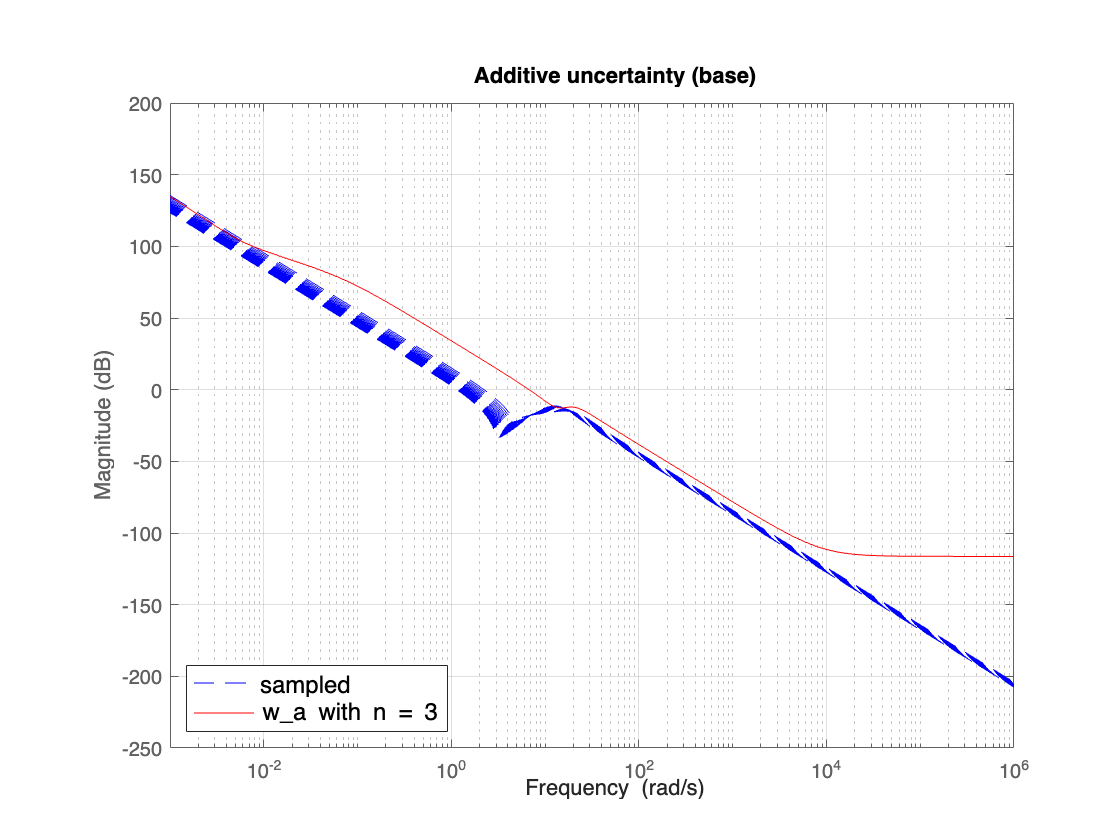

figure()
bodemag(Pc_unc_samp,'b--', Pc_nom + Wc_add,'r'), grid;
title('Additive uncertainty (base)');
Leg = legend('sampled','w_a with n = 3');
set(Leg,'FontSize',12,'Location','SouthWest');

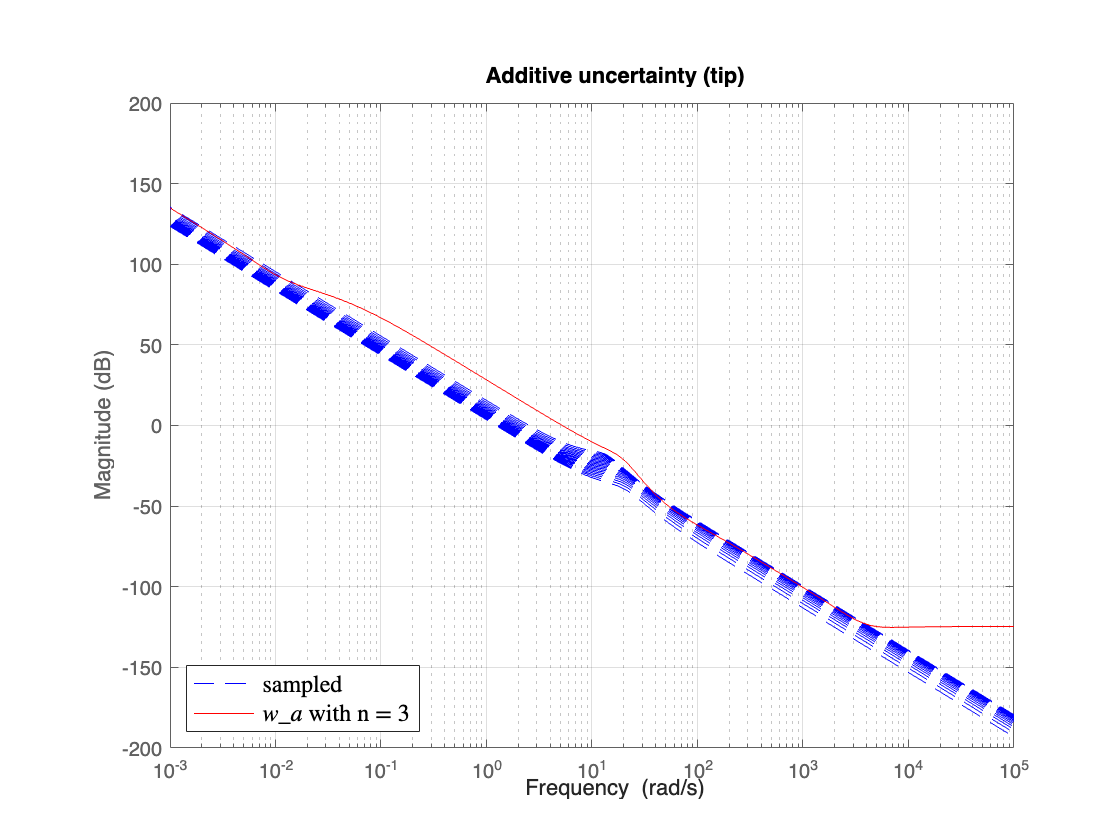

figure()
bodemag(Pt_unc_samp,'b--', Pt_nom + Wt_add,'r'), grid;
title('Additive uncertainty (tip)');
Leg = legend('sampled','$w_a$ with n = 3','Interpreter','latex');
set(Leg,'FontSize',12,'Location','SouthWest');

% Full complex additive
Pc_add = Pc_nom + Wc_add*Delta;
Pt_add = Pt_nom + Wt_add*Delta;

CLoop_add_c = feedback(Cc*Pc_add,1);
CLoop_add_t = feedback(C1t*Pt_add,1);

[stabmarg_add_c,wc_fa_c] = robstab(CLoop_add_c)

stabmarg_add_c = struct with fields:
           LowerBound: 0.1290
           UpperBound: 0.1293
    CriticalFrequency: 0.4032


wc_fa_c = struct with fields:
    delta: [1×1 ss]


[stabmarg_add_t,wc_fa_t] = robstab(CLoop_add_t)

stabmarg_add_t = struct with fields:
           LowerBound: 0.2864
           UpperBound: 0.2870
    CriticalFrequency: 0.3086


wc_fa_t = struct with fields:
    delta: [1×1 ss]


Results are actually very similar, therefore we can conclude that the system is not stable with respect to unstructured additive uncertanties. In fact, the necessary and sufficient condition fails:

$||w_a \left(s\right)C\left(s\right)S_{\textrm{nom}} \left(s\right)||_{\infty \;} <1$ is not at all verified

hinfnorm(Wc_add*Cc*loopsens(Pc_nom,Cc).So)

ans = 7.7364

hinfnorm(Wt_add*C1t*loopsens(Pt_nom,C1t).So)

ans = 3.4843

This representation of uncertainty is too conservative.

#### Nyquist Plot for base loop function (MP)

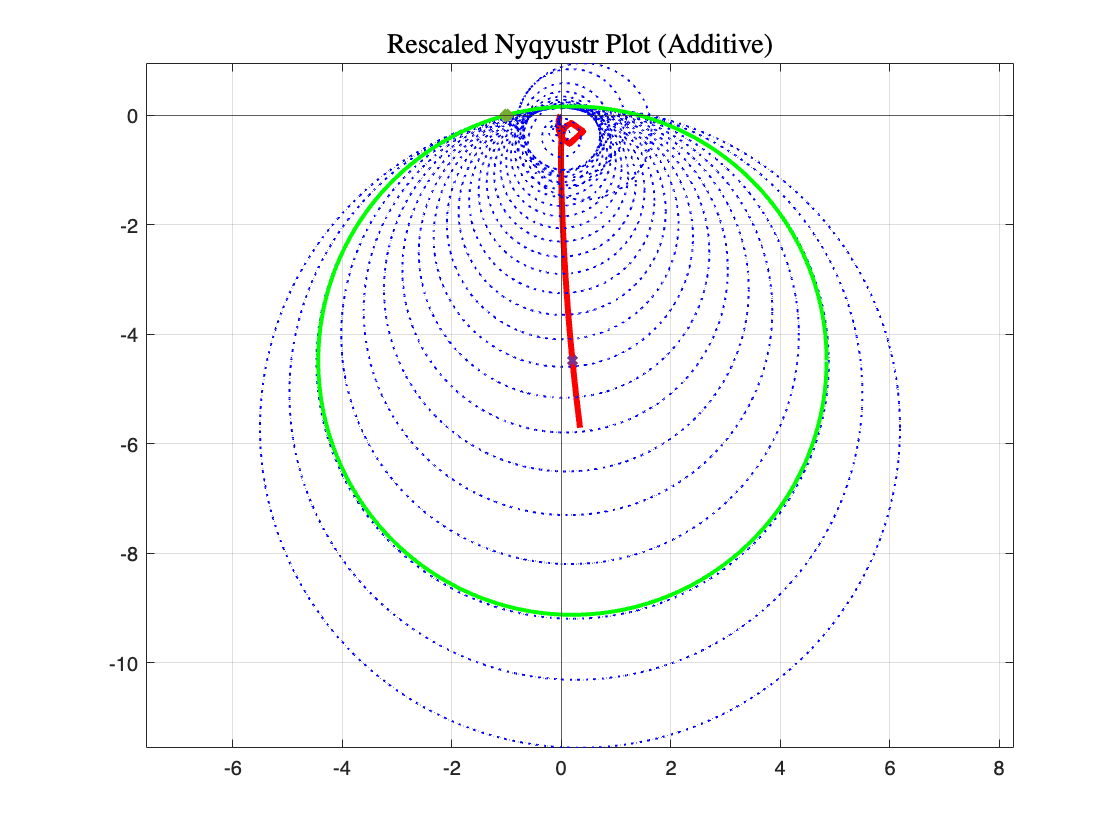

Lc_unc = Pc_unc*Cc;
Lc_nom = minreal(Lc_unc.Nominal);

om = logspace(-0.5,2,50);
n = length(om);
alpha = 0:0.01:2*pi;

[ReLc,ImLc]=nyquist(Lc_nom, om);
crit_w = stabmarg_add_c.CriticalFrequency;
upper_b = stabmarg_add_c.UpperBound;
figure()
grid
plot(ReLc(:),ImLc(:),'-r','LineWidth',3), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Lc_nom,om(i));
    %ReLc
    [radius,radiusp]=bode((Cc*Wc_add), om(i));
    plot(ReLw + upper_b*radius*cos(alpha),ImLw + upper_b*radius*sin(alpha),':b','LineWidth',1);
end
[ReLw,ImLw]=nyquist(Lc_nom,crit_w);
[radius,radiusp]=bode((Cc*Wc_add), crit_w);
plot(ReLw + upper_b*radius*cos(alpha),ImLw + upper_b*radius*sin(alpha),'g',ReLw,ImLw,"x", 'LineWidth',2)
plot(-1,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Rescaled Nyqyustr Plot (Additive)','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',14);
xline(0);
yline(0);
hold off

Rescaled radius passes through (-1,0) at critical frequency. Non rescaled value would surppass it.

### Multiplicative Unstructured Uncertainty

On the other hand, the multiplicative modeling gives opposite results.

% ucover multiplicative
[~,info_mul_c] = ucover(Pc_unc_samp,Pc_nom,3);
[~,info_mul_t] = ucover(Pt_unc_samp,Pt_nom,3);

% uncertanty weights
Wc_mul = info_mul_c.W1;
Wt_mul = info_mul_t.W1;

Both systems have stability margin greater than 1. Let's check if using the full complex formulation gives the same result.

% Full complex multiplicative
Pc_mul = Pc_nom*(1+Wc_mul*Delta);
Pt_mul = Pt_nom*(1+Wt_mul*Delta);

% Closed Loop Multiplicative
CLoop_mul_c = feedback(Cc*Pc_mul,1);
CLoop_mul_t = feedback(C1t*Pt_mul,1);

% Multiplicative stability margins
[stabmarg_mul_c,wc_fm_c] = robstab(CLoop_mul_c)

stabmarg_mul_c = struct with fields:
           LowerBound: 1.1294
           UpperBound: 1.1316
    CriticalFrequency: 1.2198e-06


wc_fm_c = struct with fields:
    delta: [1×1 ss]


[stabmarg_mul_t,wc_fm_t] = robstab(CLoop_mul_t)

stabmarg_mul_t = struct with fields:
           LowerBound: 1.3442
           UpperBound: 1.3469
    CriticalFrequency: 0


wc_fm_t = struct with fields:
    delta: [1×1 ss]


$||w_m \left(s\right)T_{\textrm{nom}} \left(s\right)||_{\infty } <1\;$are verified in both systems

hinfnorm(Wc_mul*loopsens(Pc_nom,Cc).To) 

ans = 0.8858

hinfnorm(Wt_mul*loopsens(Pt_nom,C1t).To)

ans = 0.7431

This representation is still conservative but not as much as additive repres.

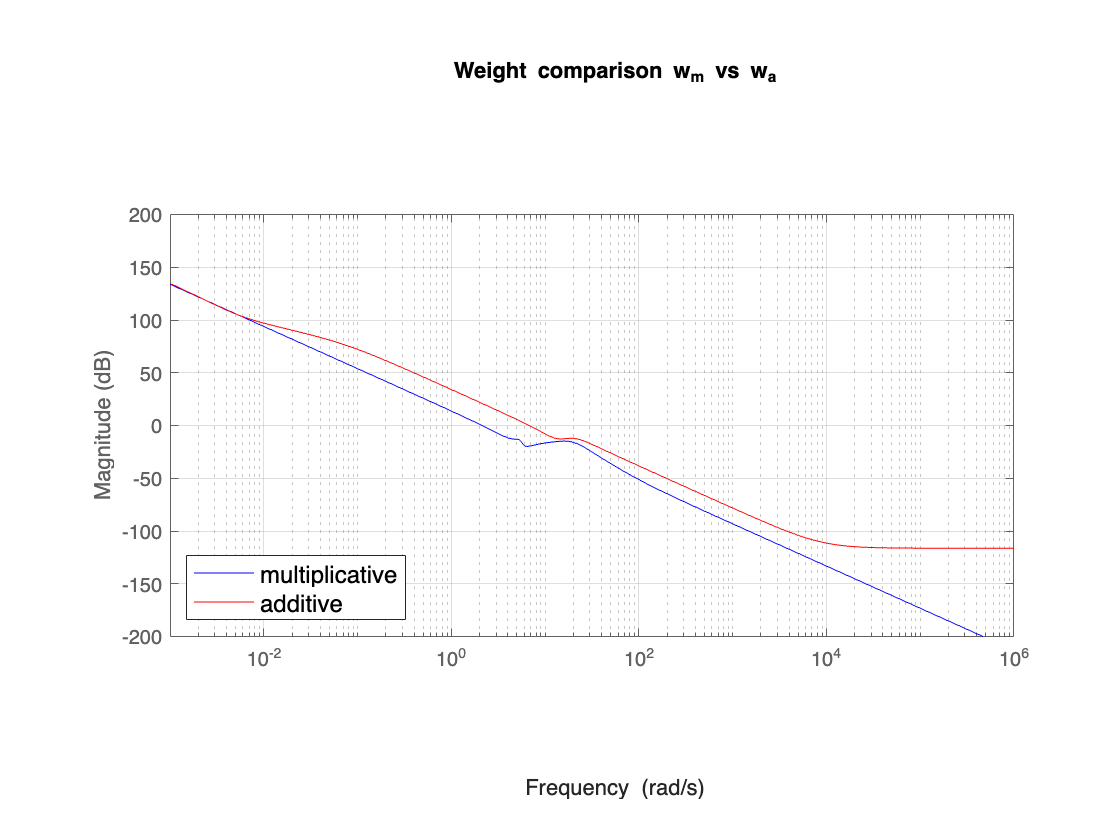

% Weight Comparison
figure()
bodemag(Pc_nom*Wc_mul,'b', Pc_nom + Wc_add,'r'), grid;
pbaspect([2 1 1])
title('Weight comparison w_m vs w_a');
Leg = legend('multiplicative','additive');
set(Leg,'FontSize',12,'Location','SouthWest');

We see that the additive weight is almost always larger than the multiplicative one, i.e. more conservative.

## CASE III: Unmodelled dynamics

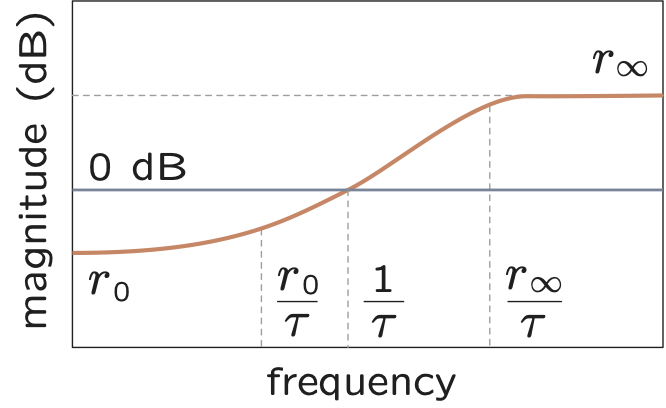

Add uncertainty from the unmodelled dynamics coming from approximations.

r_inf = 2;      % 200% at high frequency
r0 = 0.01;       % 1% at low frequerncy
tau     = 1/25;  % 100% unc. at w = 25

Wun = r0*(1+s*tau/r0)/(1+s*tau/r_inf);

Pc_u = Pc_unc*(1 + Wun*Delta);
Pc_u_samp  = usample(Pc_u,20);

Pc_u_array = frd(Pc_u_samp,logspace(-3,3,200));
[Pw_u,info_u] = ucover(Pc_u_array,Pc_nom,7);


#### Choose multiplicative representation

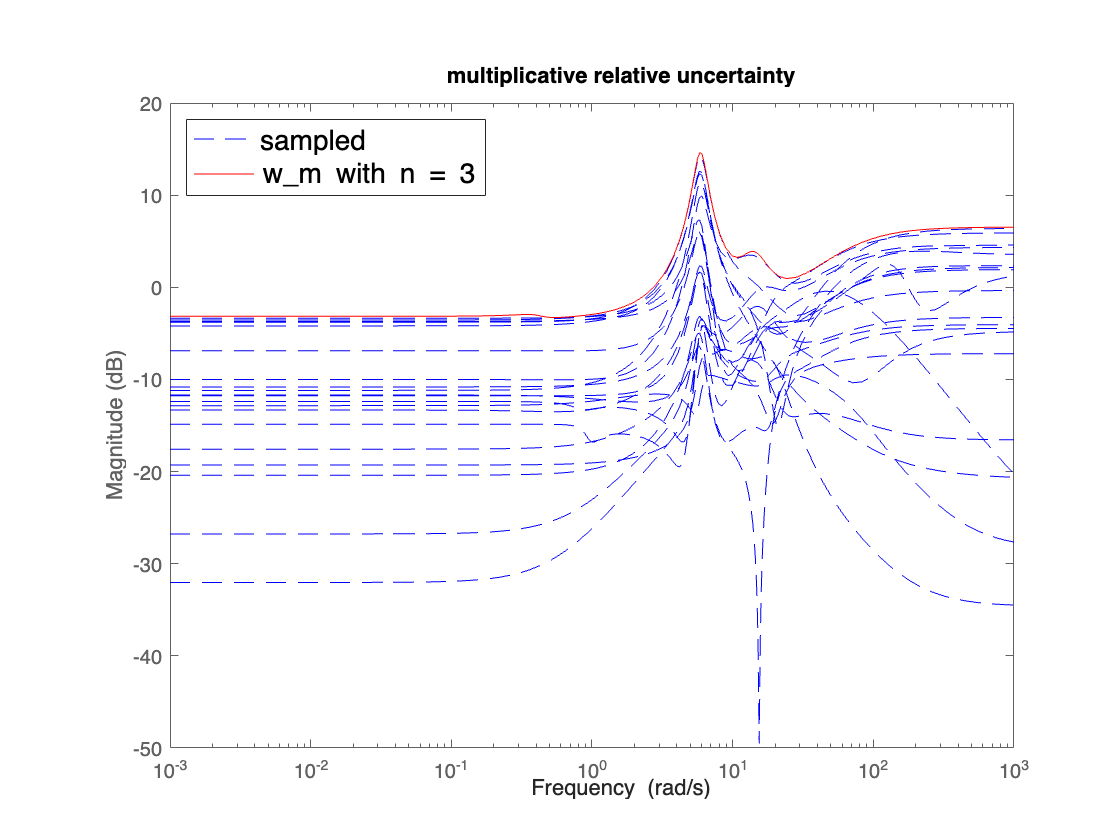

Rel_P = (Pc_nom-Pc_u_samp)/Pc_nom;
bodemag(Rel_P,'b--',info_u.W1,'r',{10e-4,10e+2});
title('multiplicative relative uncertainty')
Leg = legend('sampled','w_m with n = 3');
set(Leg,'FontSize',14,'Location','northwest');

Cl_c = feedback(Cc*Pw_u,1);
[stabmarg_u,wcu_u]= robstab(Cl_c)   

stabmarg_u = struct with fields:
           LowerBound: 0.7947
           UpperBound: 0.7963
    CriticalFrequency: 6.7004


wcu_u = struct with fields:
    Pc_u_array_InputMultDelta: [1×1 ss]


Lc_u = Pc_u*Cc;
Lu_nom = minreal(Lc_u.Nominal);

1 state removed.


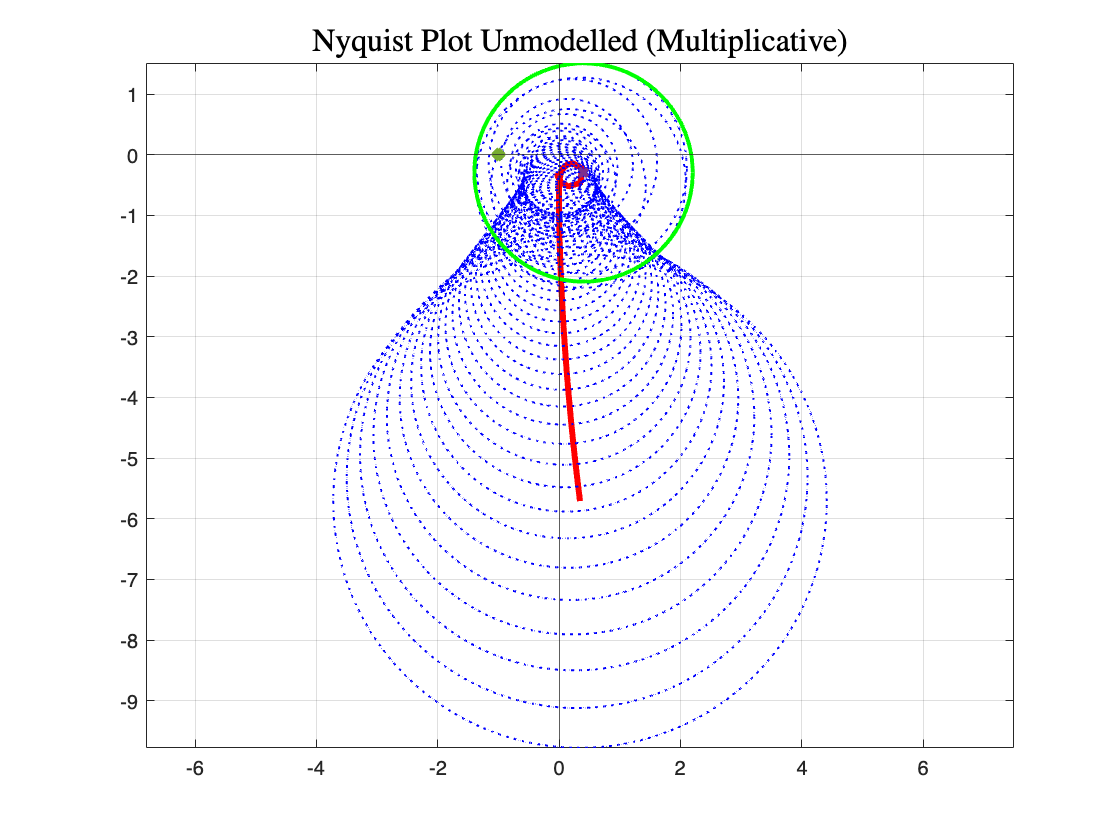


om = logspace(-0.5,1,50);
n = length(om);
alpha = 0:0.01:2*pi;

[ReLc,ImLc]=nyquist(Lu_nom, om);
crit_w = stabmarg_u.CriticalFrequency;
figure()
grid
plot(ReLc(:),ImLc(:),'-r','LineWidth',3), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Lu_nom,om(i));
    [radius,~]=bode((Lu_nom*info_u.W1), om(i));
    plot(ReLw + radius*cos(alpha),ImLw + radius*sin(alpha),':b','LineWidth',1);
end
[ReLw,ImLw]=nyquist(Lu_nom,crit_w);
[radius,radiusp]=bode((Lu_nom*info_u.W1), crit_w);
plot(ReLw + radius*cos(alpha),ImLw + radius*sin(alpha),'g',ReLw,ImLw,"x", 'LineWidth',2)
plot(-1,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Nyquist Plot Unmodelled (Multiplicative)','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',16);
xline(0);
yline(0);
hold off

hinfnorm(info_u.W1*loopsens(Pc_nom,Cc).To)

ans = 1.2559

## CASE IV: Neglected dynamics

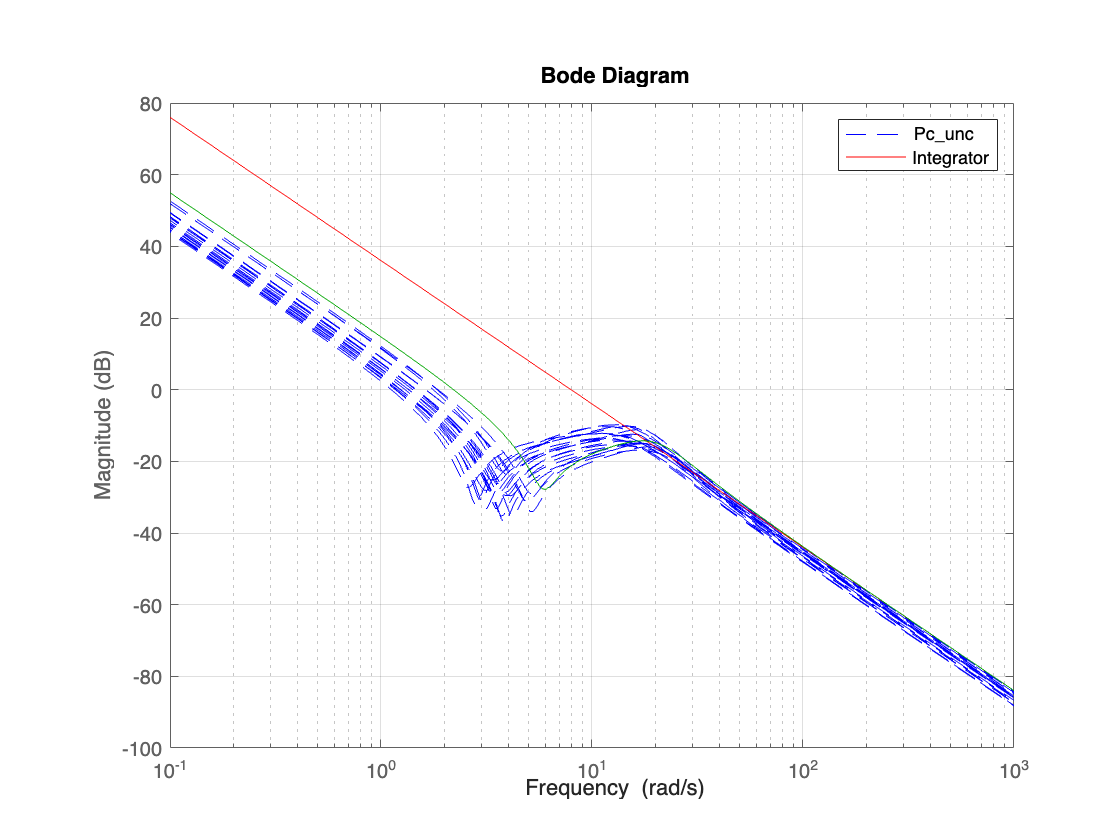

Pc_n = 63.245/s^2;
Pc_neg = Pc_unc/Pc_n;

figure()
bodemag(Pc_unc,'--b',Pc_n,'r', Pc_nom, 'g'), grid
legend('Pc_{unc}', 'Integrator')

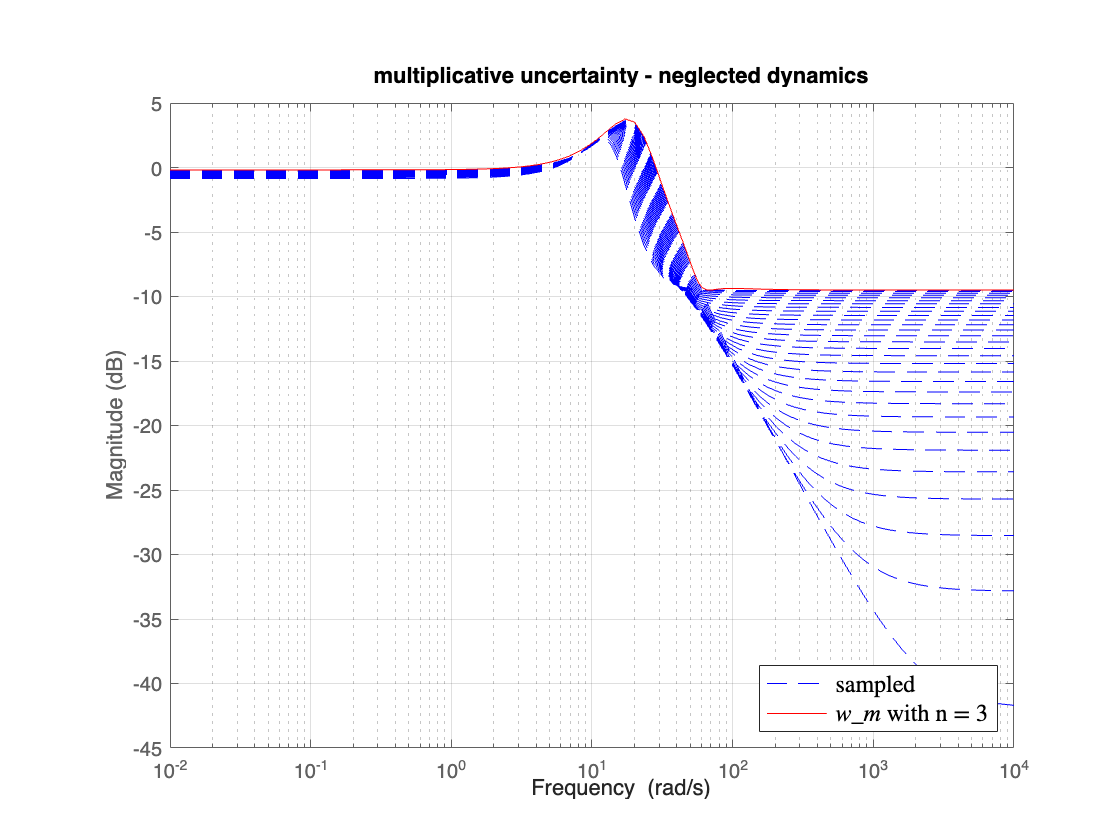

Ptot_sampled = gridureal(Pc_unc,30);
[PwNd,InfoNd] = ucover(Ptot_sampled,Pc_n,5);
%Rel_PNd = Pne-1; % here I should have sampled Pne
Rel_PNd = (Ptot_sampled - Pc_n)/Pc_n;
bodemag(Rel_PNd,'b--',InfoNd.W1,'r',{10e-3,10e+3}), grid;
title('multiplicative uncertainty - neglected dynamics')
Leg = legend('sampled','$w_m$ with n = 3','Interpreter','latex');
set(Leg,'FontSize',12,'Location','SouthEast');

%% Sensitivity Weight
Msc = 1.2;
B3sc = 1;
Asc = 0.2;
nc = 1;
wSc = ((s/(Msc)^(1/nc)+B3sc)/(s+B3sc*(Asc)^(1/nc)))^nc;

wSuc = 1/50;



[Cc2,CLc2,GAMc2] = mixsyn(Pc_n,wSc, wSuc,[]);
GAMc2

GAMc2 = 0.8478

P_Ndfull = Pc_n*(1+InfoNd.W1*Delta);
CLoopNd = feedback(P_Ndfull*Cc2,1);
[stabmargNd,wcuNd] = robstab(CLoopNd) 

stabmargNd = struct with fields:
           LowerBound: 1.0339
           UpperBound: 1.0360
    CriticalFrequency: 1.0443e-10


wcuNd = struct with fields:
    delta: [1×1 ss]


CLoop2 = feedback(Pc_unc*Cc2,1);
[stabmarg2,wcu2] = robstab(CLoop2) 

stabmarg2 = struct with fields:
           LowerBound: 1.0369
           UpperBound: 1.0416
    CriticalFrequency: 0


wcu2 = struct with fields:
        J: 477.3701
     Phi0: 6.8525
      om1: 12.5168
      om2: 212.5176
    zeta1: 0.3583


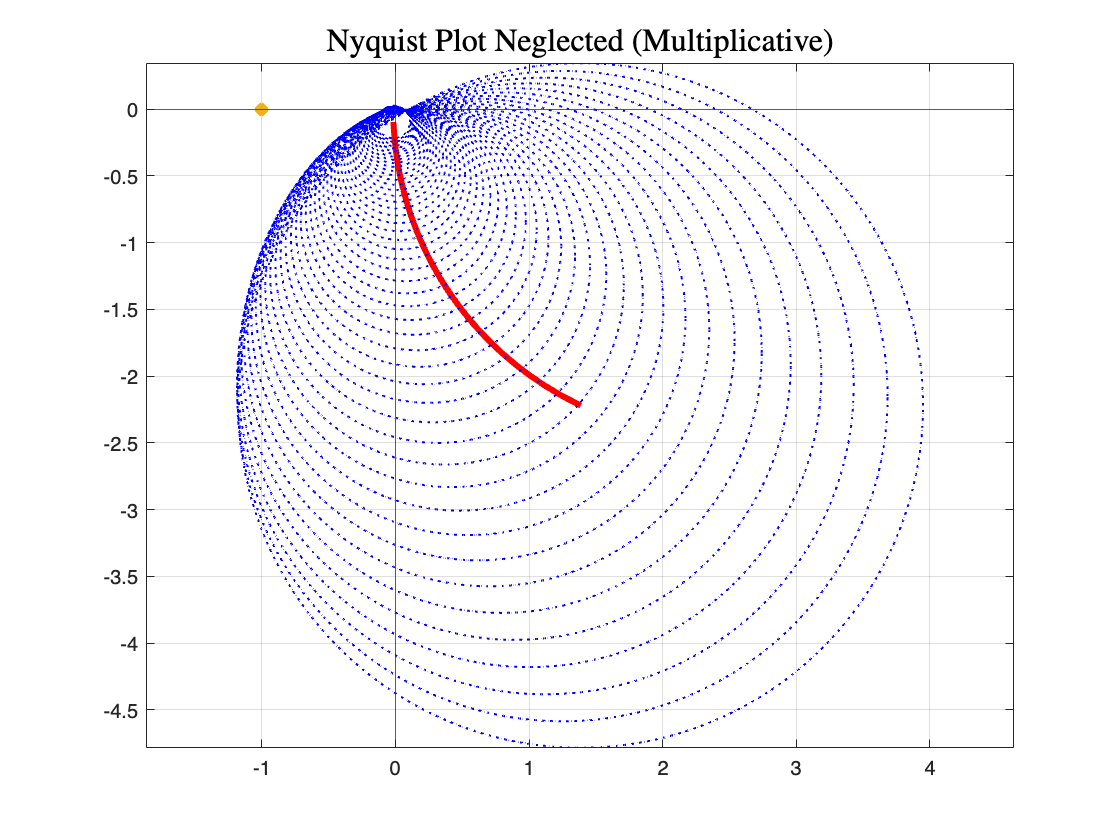

Lc_n = Pc_unc*Cc2;
Ln_nom = Pc_n*Cc2;

[ReLc,ImLc]=nyquist(Ln_nom, om);
figure()
grid
plot(ReLc(:),ImLc(:),'-r','LineWidth',3), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Ln_nom,om(i));
    [radius,~]=bode((Ln_nom*InfoNd.W1), om(i));
    plot(ReLw + radius*cos(alpha),ImLw + radius*sin(alpha),':b','LineWidth',1);
end
plot(-1,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Nyquist Plot Neglected (Multiplicative)','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',16);
xline(0);
yline(0);
hold off


hinfnorm(InfoNd.W1*loopsens(Pc_n,Cc2).To)

ans = 1.0112

# Augmented Plant Framework

%{ 
%Classical Choice

Ms1 = 1.001;
B3s1 = 2; 
As1 = 0.01;
n1 = 1;

wS1 = ((s/(Ms1)^(1/n1)+B3s1)/(s+B3s1*(As1)^(1/n1)))^n1;

wSu1 = 1/10;
Pe = [wS1 -Pt*wS1;
      0 wSu1;
      wS1 -Pc*wS1];
%}

gamma_aug = 9.1878

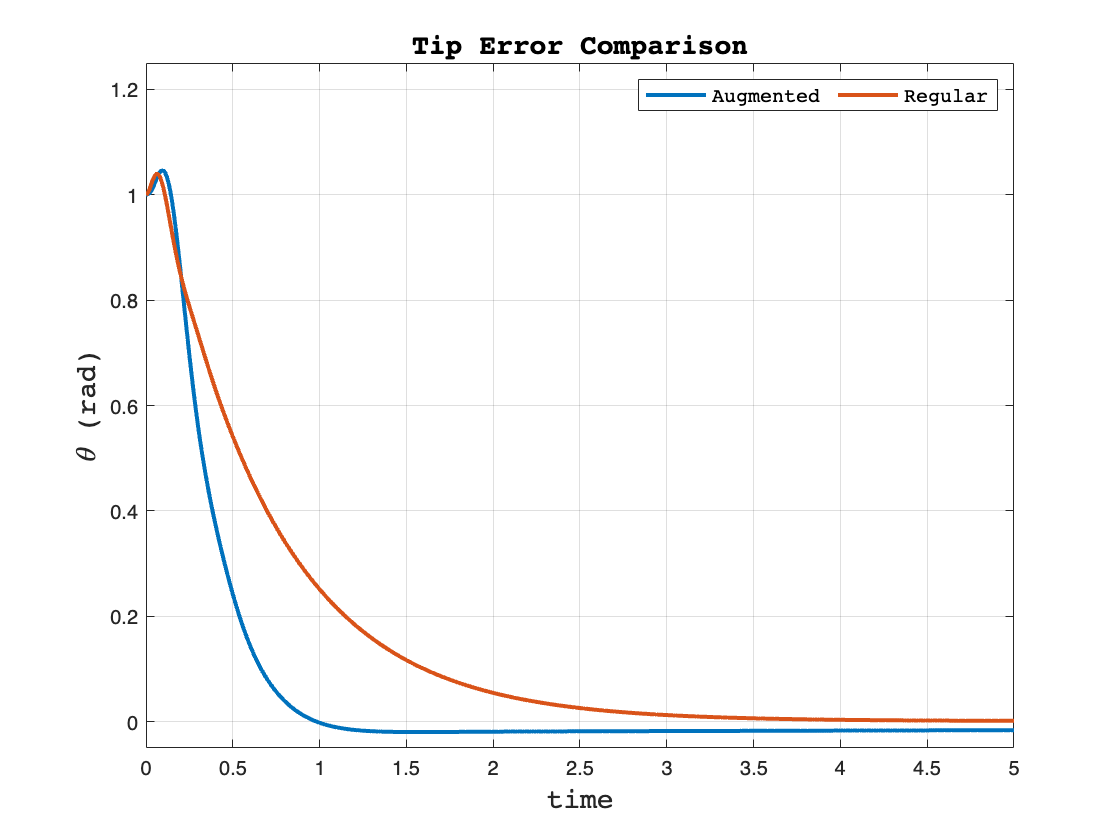


% Weird outperforming choice
Pe = [1 -Pt/tf(0.1);
      0 1;
      1 -Pc];

Pe = zpk(Pe);

ncont = 1; % one control signal, u
nmeas = 1; % one measurement signal, ey_c
opts = hinfsynOptions('Method','LMI','Display','off');

[C_aug,~,gamma_aug] = hinfsyn(Pe,nmeas,ncont,9.5,opts);
gamma_aug
Pc.u = 'u';
Pc.y = 'yc';
Pt.u = 'u';
Pt.y = 'yt';

C_aug.u = 'v';
C_aug.y = 'u';
Sum1 = sumblk('ey_t = r - yt');
Sum2 = sumblk('v = r - yc');
G = connect(Pc,Pt,C_aug,Sum1,Sum2,{'r'},{'ey_t','u'});

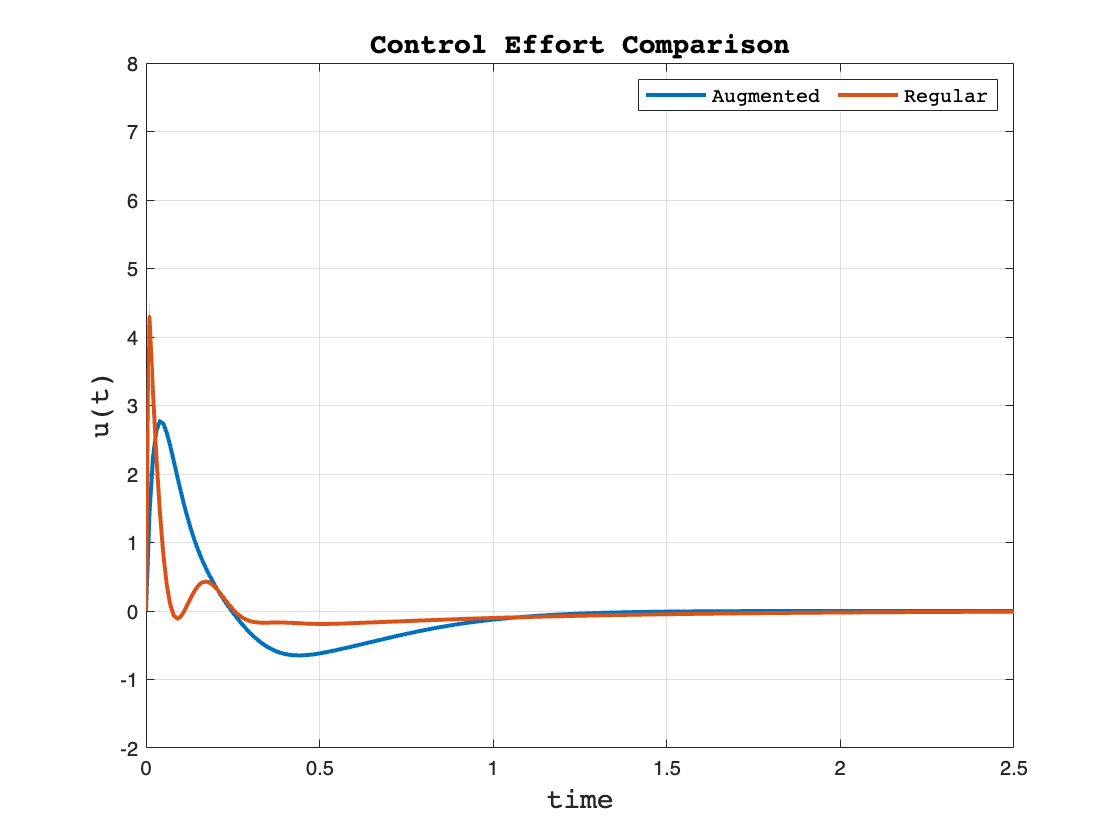

[ey_aug, t1] = step(G({'ey_t'},:), [0:0.01:10]);
[ey_t, t2] = step(CLoop_t1.So, [0:0.01:10]);

figure()
plot(t1,ey_aug,t2,ey_t,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('\theta (rad)','FontName','courier','FontSize',14)
title('Tip Error Comparison', 'FontName','courier','FontSize',14)
xlim([0,5])
ylim([-0.05,1.25])
legend('Augmented', 'Regular','FontName','courier','FontSize',10,...

    'Location','northeast','NumColumns',3)
[u_aug, t1] = step(G({'u'},:), [0:0.01:10]);
[u_t, t2] = step(CLoop_t1.CSo, [0:0.01:10]);

figure()
plot(t1,u_aug,t2,u_t,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('u(t)','FontName','courier','FontSize',14)
title('Control Effort Comparison', 'FontName','courier','FontSize',14)
xlim([0,2.5])
ylim([-2,8])
legend('Augmented', 'Regular','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)

# Extension: Multiple Nodes

Considering 3 elastic modes ($n_e = 3
$) the matrices are


$$M = \left[\matrix{J & 0  & 0  & 0\cr 0 & 1 & 0  & 0\cr
 0 & 0 & 1  & 0\cr  0 & 0 & 0  & 1\cr}  \right], \quad
D = \left[\matrix{0 & 0 & 0 & 0\cr 0 & 2 \zeta_1 \omega_1 &0 & 0\cr
0 & 0 &  2 \zeta_2 \omega_2 & 0\cr 0 & 0 & 0 &  2 \zeta_3\omega_3\cr}  \right]$$



$$K = \left[\matrix{0 & 0 & 0 & 0\cr 0 & \omega_1^2 & 0 & 0\cr
0 & 0 &  \omega_2^2 & 0\cr 0 & 0 &  0 & \omega_3^2\cr}  \right], \quad
B_p = \left[\matrix{1 \cr \Phi'_1(0) \cr \Phi'_2(0)  \cr \Phi'_3(0)}  \right]$$


% Execute for calculating system parameters
EulerBeam_Modeling3Modes

omega=sqrt(Om2);

M = [J, zeros(1,3);zeros(3,1),eye(3)];
% damping coefficients 
zeta_values=0.4;
zeta=ones(1,3)*zeta_values;
D = [0,zeros(1,3);zeros(3,1),diag(2*zeta.*omega)];
K = [0, zeros(1,3);zeros(3,1), diag(Om2)];
Bp = [1; transpose(Phip0)];

#### State space representation

A_d    = [zeros(4),eye(4);-inv(M)*K, -inv(M)*D]; % damping
B      = [zeros(4,1);inv(M)*Bp];
C_bas  = [transpose(Bp),zeros(1,4)];

ans =
 
  429.79 (s^2 + 0.7525s + 24.98) (s^2 + 21.71s + 974.8) (s^2 + 67.25s + 7663)
  ---------------------------------------------------------------------------
   s^2 (s^2 + 16.43s + 421.6) (s^2 + 44.7s + 3123) (s^2 + 81.09s + 1.027e04)
 
Continuous-time zero/pole/gain model.
Model Properties


C_tip  = [1,PhiL,zeros(1,4)];

FlexBasD   = ss(A_d,B,C_bas,0);
FlexTipD   = ss(A_d,B,C_tip,0);

ans =
 
   -11.291 (s-23.75) (s+10.99) (s^2 + 137.1s + 4746) (s^2 - 95.06s + 5732)
  -------------------------------------------------------------------------
  s^2 (s^2 + 16.43s + 421.6) (s^2 + 44.7s + 3123) (s^2 + 81.09s + 1.027e04)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Transfer functions for tip and base

% Joint (Base) TF: Pc

ans =   47.5320 +58.9323i
  47.5320 -58.9323i
 -68.5544 + 6.7790i
 -68.5544 - 6.7790i
  23.7476 + 0.0000i
 -10.9922 + 0.0000i


[NumC, DenC] = ss2tf(A_d,B,C_bas,0);
Pc_mult = tf(NumC, DenC);
zpk(Pc_mult)
% Tip TF: Pt
[NumT, DenT] = ss2tf(A_d,B,C_tip,0);
Pt_mult = tf(NumT, DenT);
zpk(Pt_mult)
zero(Pt_mult)

### $H_{\infty }$ control for MP plant (base)

Use same sensitivity weights as n=1 case

%% Sensitivity Weight 1: Compromise
Msc = 1.01;
B3sc = 2; % Bandwidth Limitation
Asc = 0.01;
nc = 1;
wSc = ((s/(Msc)^(1/nc)+B3sc)/(s+B3sc*(Asc)^(1/nc)))^nc;

wSuc = 1/10;

GAMc = 1.0090




[Cc_mult,CLc,GAMc] = mixsyn(Pc_mult,wSc, wSuc,[]);
GAMc
CLoop_c_mult = loopsens(Pc_mult,Cc_mult);

### $H_{\infty }$ control for NMP plant (tip)

%% Sensitivity Weight 1: Compromise
Ms1 = 1.1;
B3s1 = 1.4; % Bandwidth Limitation
As1 = 0.001;
n1 = 1;

wS1 = ((s/(Ms1)^(1/n1)+B3s1)/(s+B3s1*(As1)^(1/n1)))^n1;

wSu1 = tf(1/10);

GAM1t = 1.0488


[C1t_mult,CL1t,GAM1t] = mixsyn(Pt_mult,wS1, wSu1,[]);
GAM1t 
CLoop_t_mult = loopsens(Pt_mult,C1t_mult);

#### Step response comparison

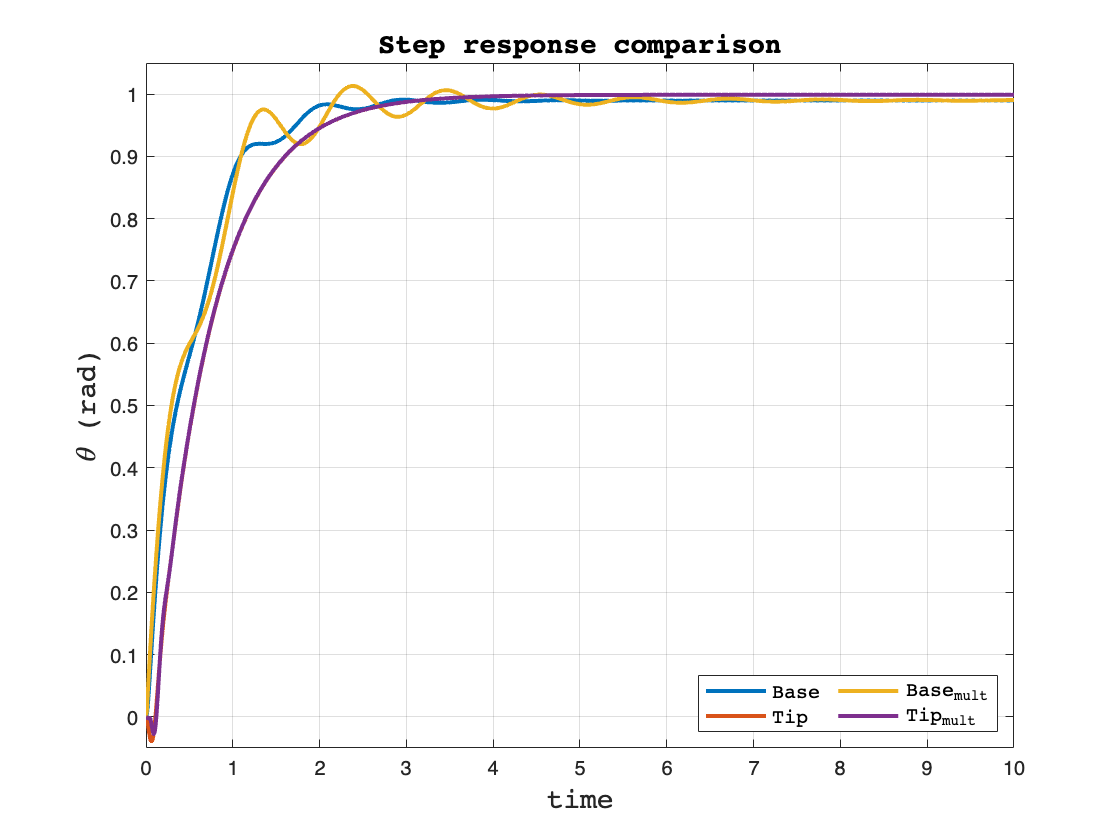

t = 0:0.01:10;

[yc_mult,~] = step(CLoop_c_mult.To, t);    % H_inf base Response
[yt_mult,~] = step(CLoop_t_mult.To, t);    % H_inf tip Response
figure()

plot(t,yc,t,y1_t,t,yc_mult,t,yt_mult,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('\theta (rad)','FontName','courier','FontSize',14)
title('Step response comparison', 'FontName','courier','FontSize',14)
ylim([-0.05,1.05])

legend('Base', 'Tip','Base_{mult}','Tip_{mult}','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

#### Control effort comparison

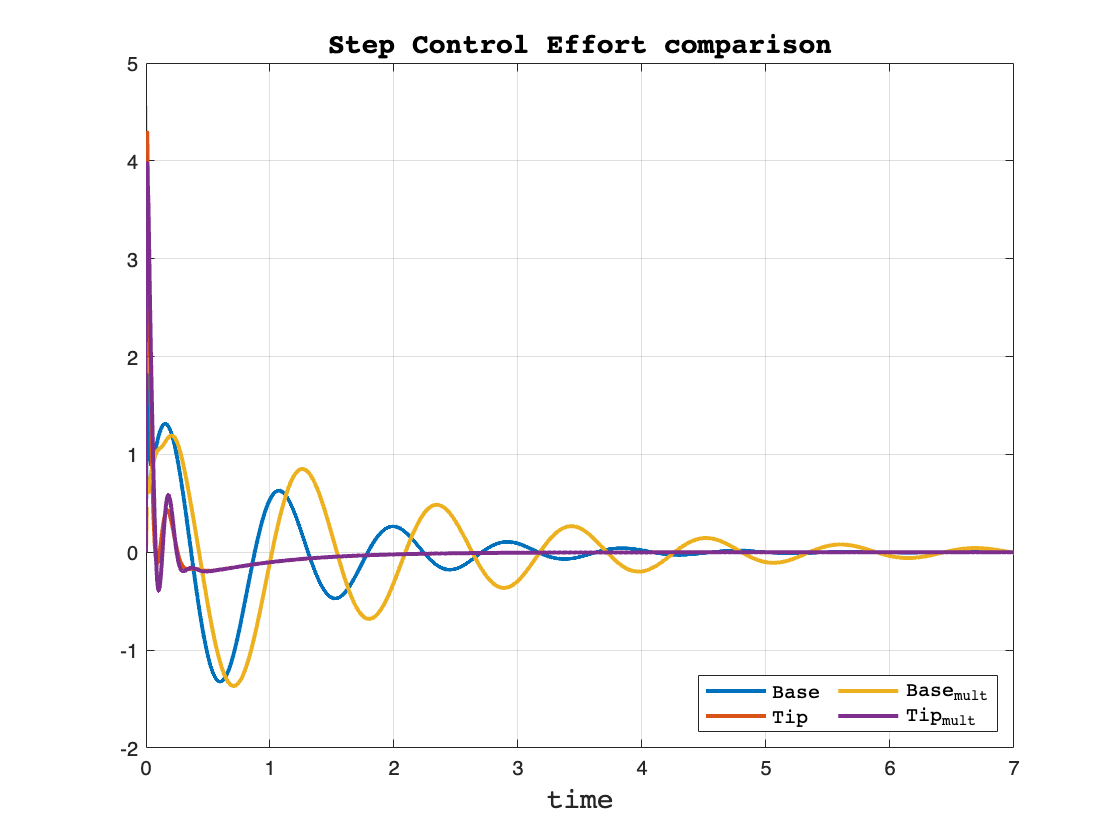

t1 = 0:0.001:10;
[u_c_mult,~] = step(CLoop_c_mult.CSo, t);    % H_inf base Control Effort
[u_t_mult,~] = step(CLoop_t_mult.CSo, t);    % H_inf base Control Effort

figure
plot(t1,u_c, t,u1_t,t,u_c_mult, t,u_t_mult,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
title('Step Control Effort comparison', 'FontName','courier','FontSize',14)
xlim([0,7])
legend('Base' , 'Tip','Base_{mult}','Tip_{mult}','FontName','courier','FontSize',10,...

    'Location','southeast','NumColumns',3)